# ELEN 133 Homework 6 -- Ayden Dauenhauer

## Question 1

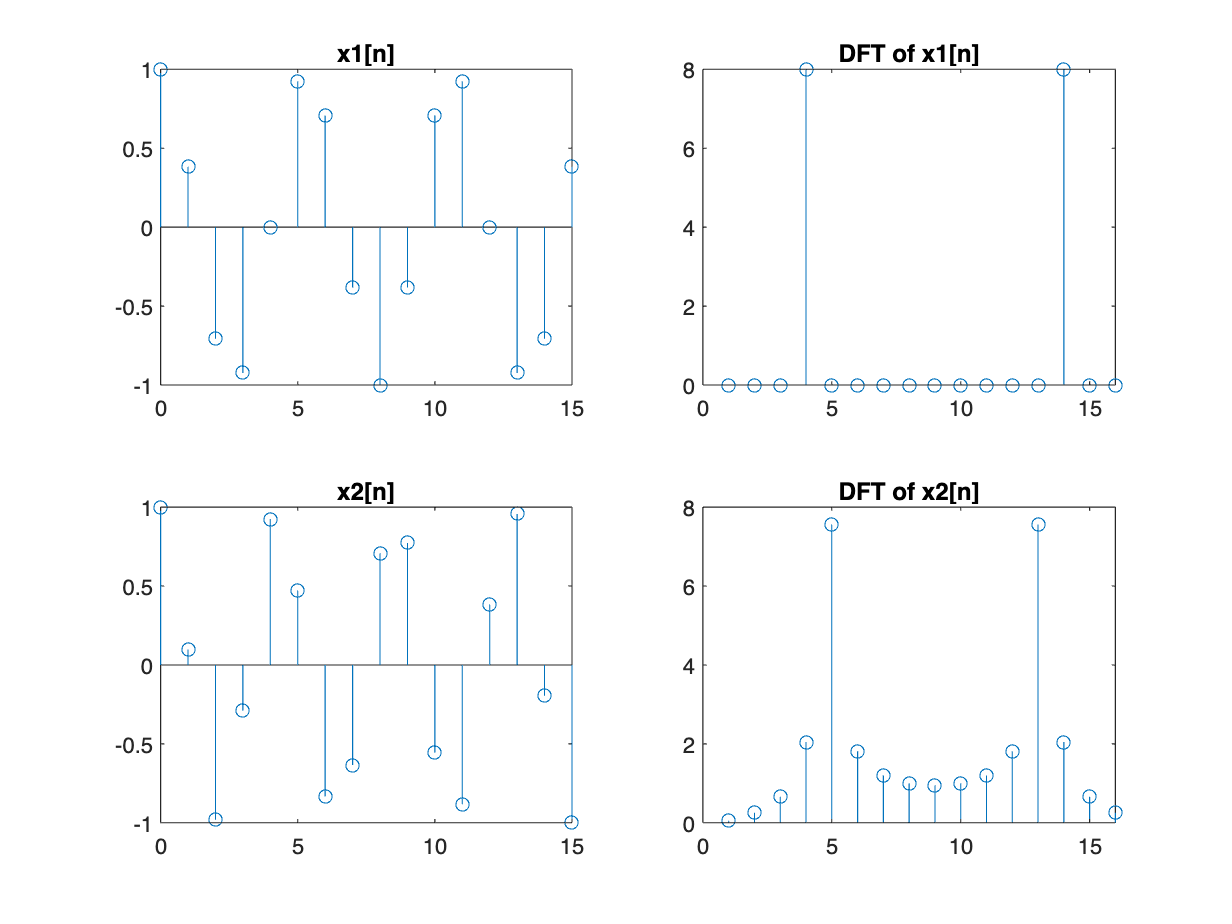

% Part a
n = 0:15;
x1 = cos((3*pi/8)*n);
x2 = cos((15*pi/32)*n);

figure;
subplot(2,2,1);
stem(n, x1);
title('x1[n]');
subplot(2,2,2);
stem(abs(fft(x1)));
title('DFT of x1[n]');
subplot(2,2,3);
stem(n, x2);
title('x2[n]');
subplot(2,2,4);
stem(abs(fft(x2)));
title('DFT of x2[n]');

**Explain the difference in the DFTs based on the relationship of the signal frequencies to the frequencies at which the DFT is evaluated.**

    x1 has  sharp peaks, whereas x2 has more scattered peaks.

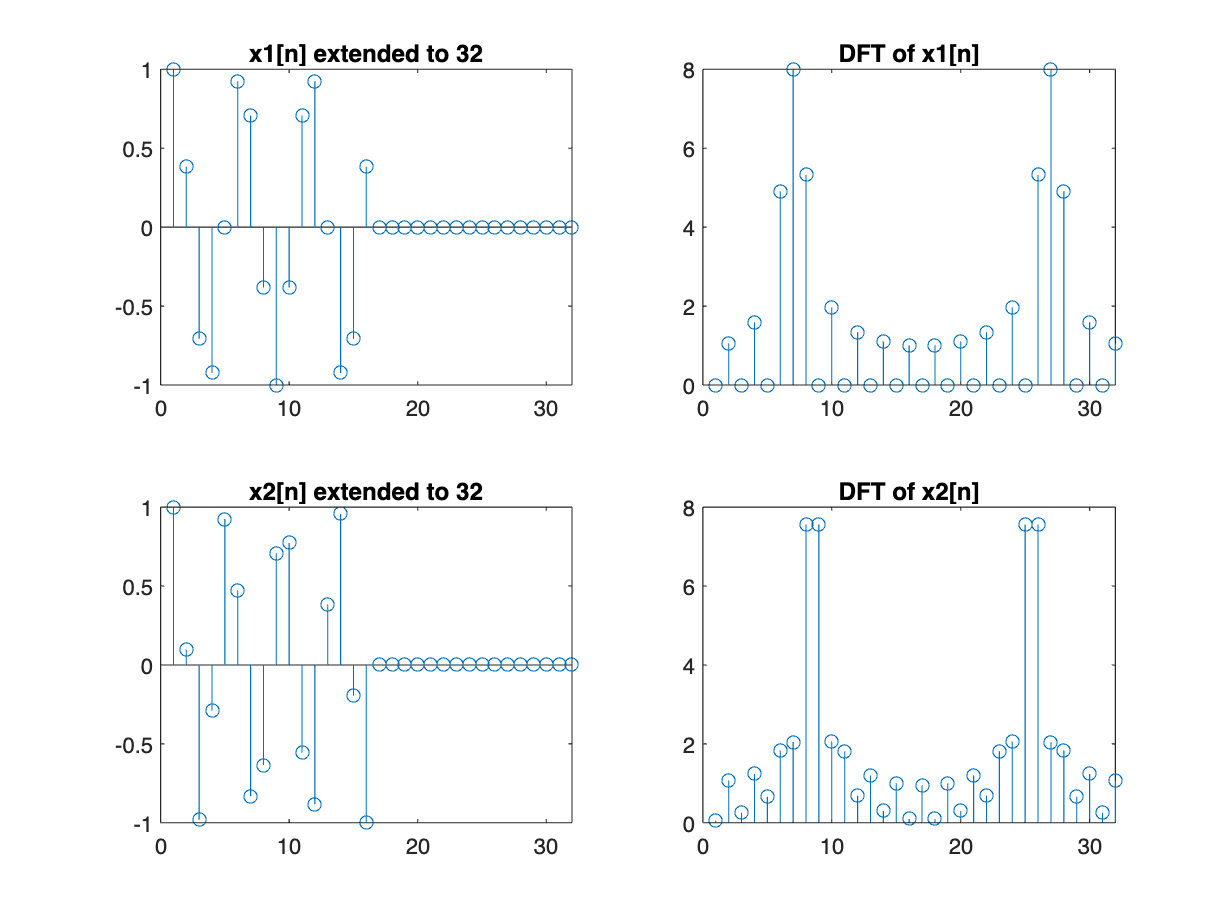

% Part b
x1 = [x1 zeros(1,16)];
x2 = [x2 zeros(1,16)];

figure;
subplot(2,2,1);
stem(x1);
title('x1[n] extended to 32');
subplot(2,2,2);
stem(abs(fft(x1)));
title('DFT of x1[n]');
subplot(2,2,3);
stem(x2);
title('x2[n] extended to 32');
subplot(2,2,4);
stem(abs(fft(x2)));
title('DFT of x2[n]');

**Explain the difference in the DFTs based on the relationship of the signal frequencies to the frequencies at which the DFT is evaluated.**

    This time x1 also has scattered peaks. x2 has sharper peaks than x1.

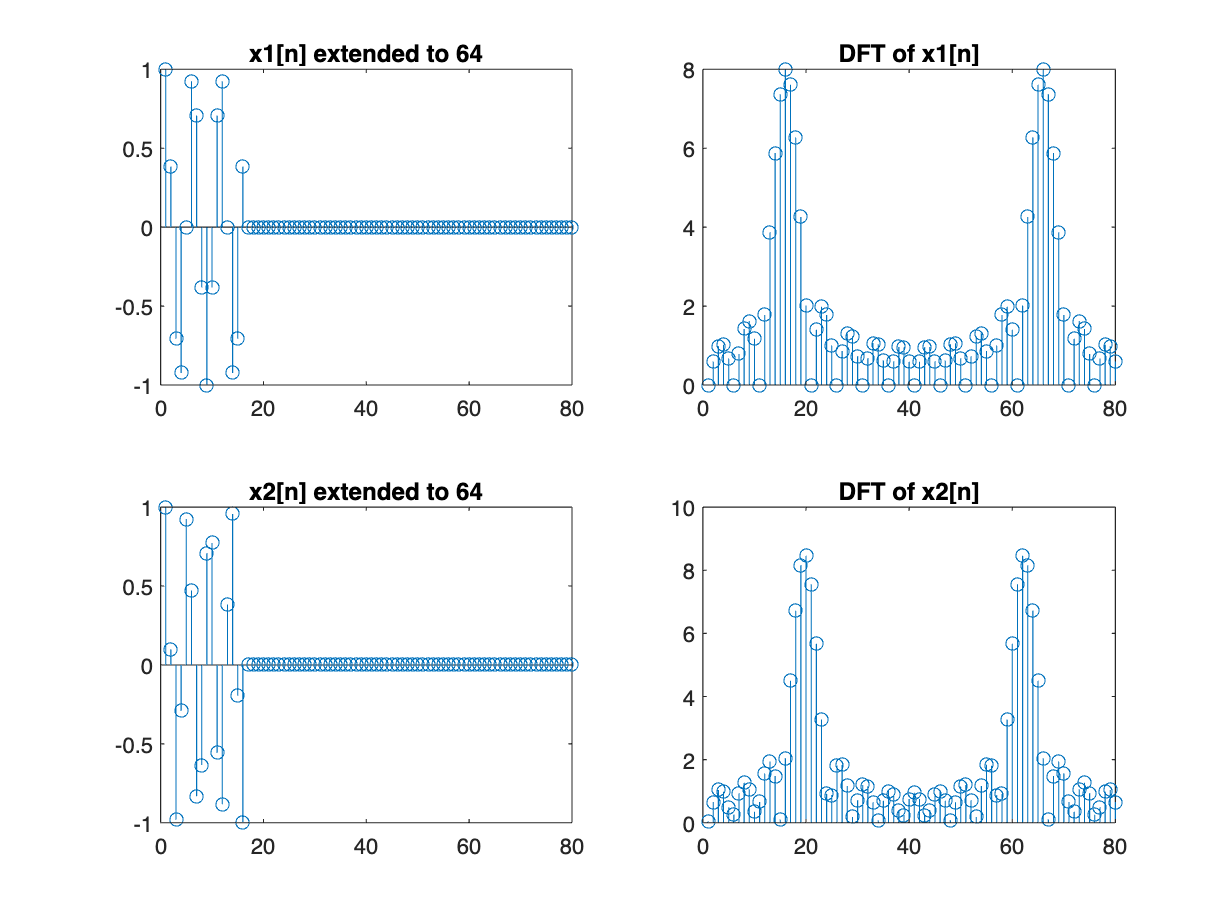

% Part c
x1 = [x1 zeros(1,48)];
x2 = [x2 zeros(1,48)];

figure;
subplot(2,2,1);
stem(x1);
title('x1[n] extended to 64');
subplot(2,2,2);
stem(abs(fft(x1)));
title('DFT of x1[n]');
subplot(2,2,3);
stem(x2);
title('x2[n] extended to 64');
subplot(2,2,4);
stem(abs(fft(x2)));
title('DFT of x2[n]');

**Explain the difference in the DFTs based on the relationship of the signal frequencies to the frequencies at which the DFT is evaluated.**

    Very similar DFTs, both have sharp peaks and some scattered peaks.

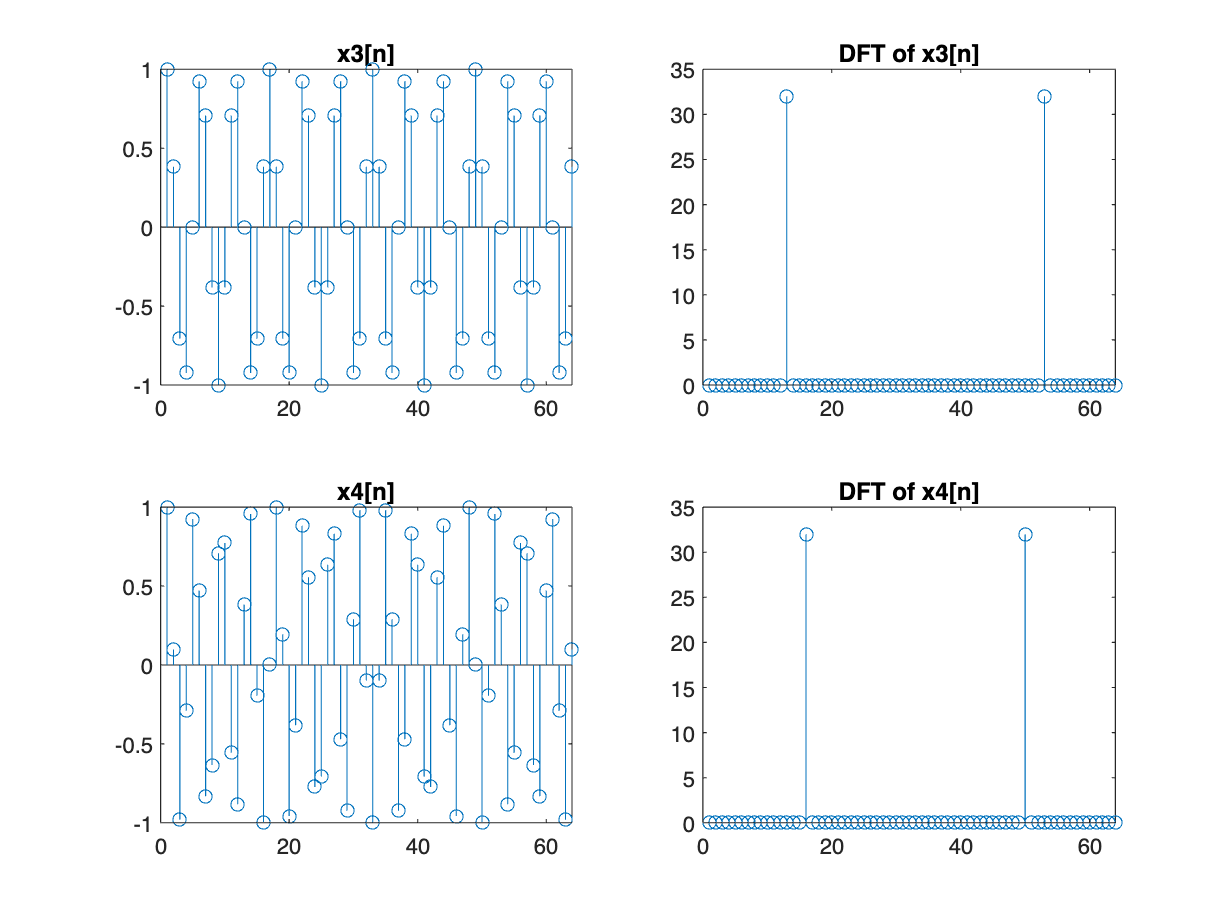

% Part d
n = 0:63;
x3 = cos((3*pi/8)*n);
x4 = cos((15*pi/32)*n);

figure;
subplot(2,2,1);
stem(x3);
title('x3[n]');
subplot(2,2,2);
stem(abs(fft(x3)));
title('DFT of x3[n]');
subplot(2,2,3);
stem(x4);
title('x4[n]');
subplot(2,2,4);
stem(abs(fft(x4)));
title('DFT of x4[n]');

**Explain the difference in the DFTs based on the relationship of the signal frequencies to the frequencies at which the DFT is evaluated.**

    Both DFTs have 2 peaks and no scattered peaks.

**Explain how these results are different from the results of part c.**

    This is easier to tell where the peak occurs since its the only peak in the DFTs.

## Question 2

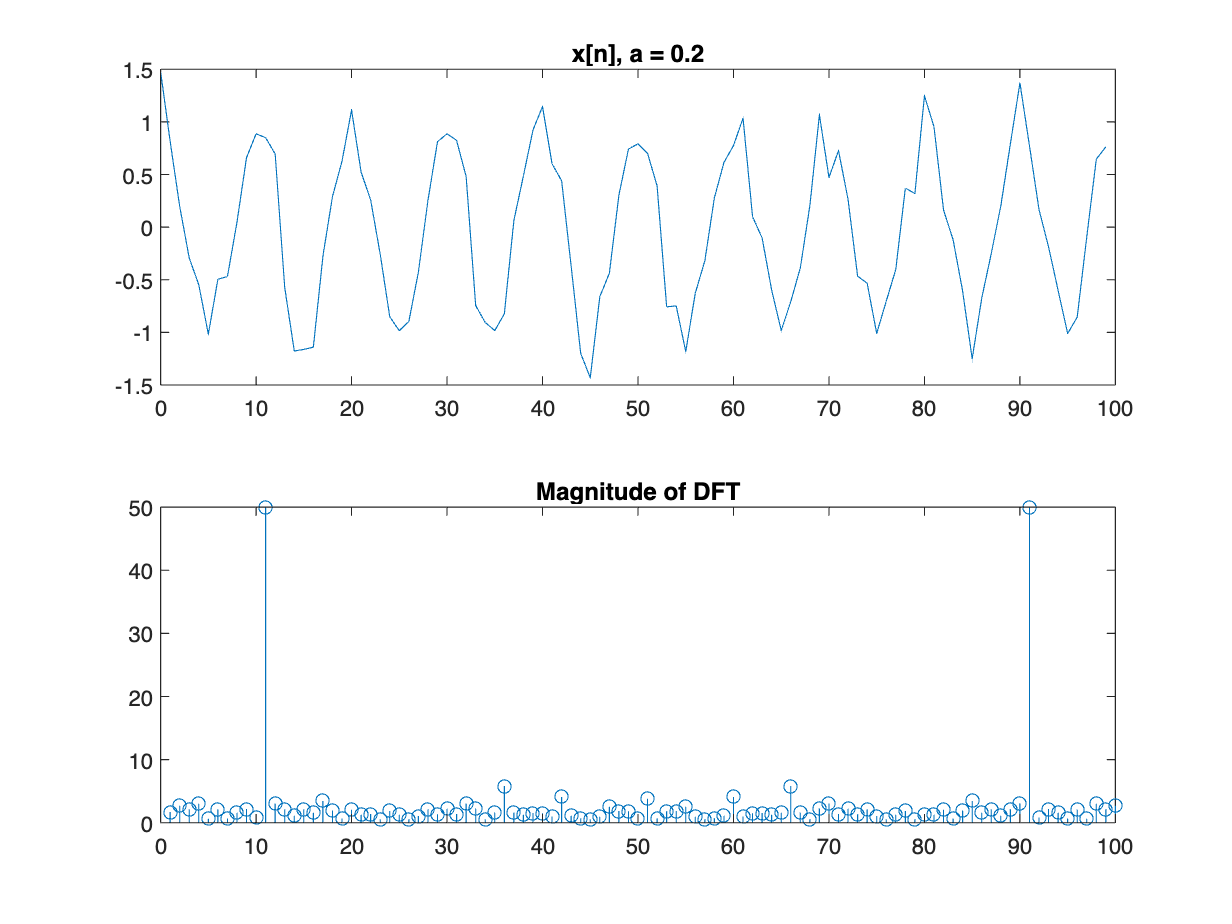

% Part a + b
N = 100;
w0 = 0.2*pi;
a = 0.2;
nv = 0:(N-1);
x = cos(w0*nv) + a*randn(size(nv));

figure;
subplot(2,1,1);
plot(nv,x);
title('x[n], a = 0.2');
subplot(2,1,2);
stem(abs(fft(x)));
title('Magnitude of DFT');

**Can you see that it is a sinusoidal signal?**

    It is a rough signal, but yes you can make out that it's sinusoidal.

**Is the value of the DFT corresponding to w0 easy to distinguish by its height relative the values at other frequencies?**

    Yes, its peak is much higher.

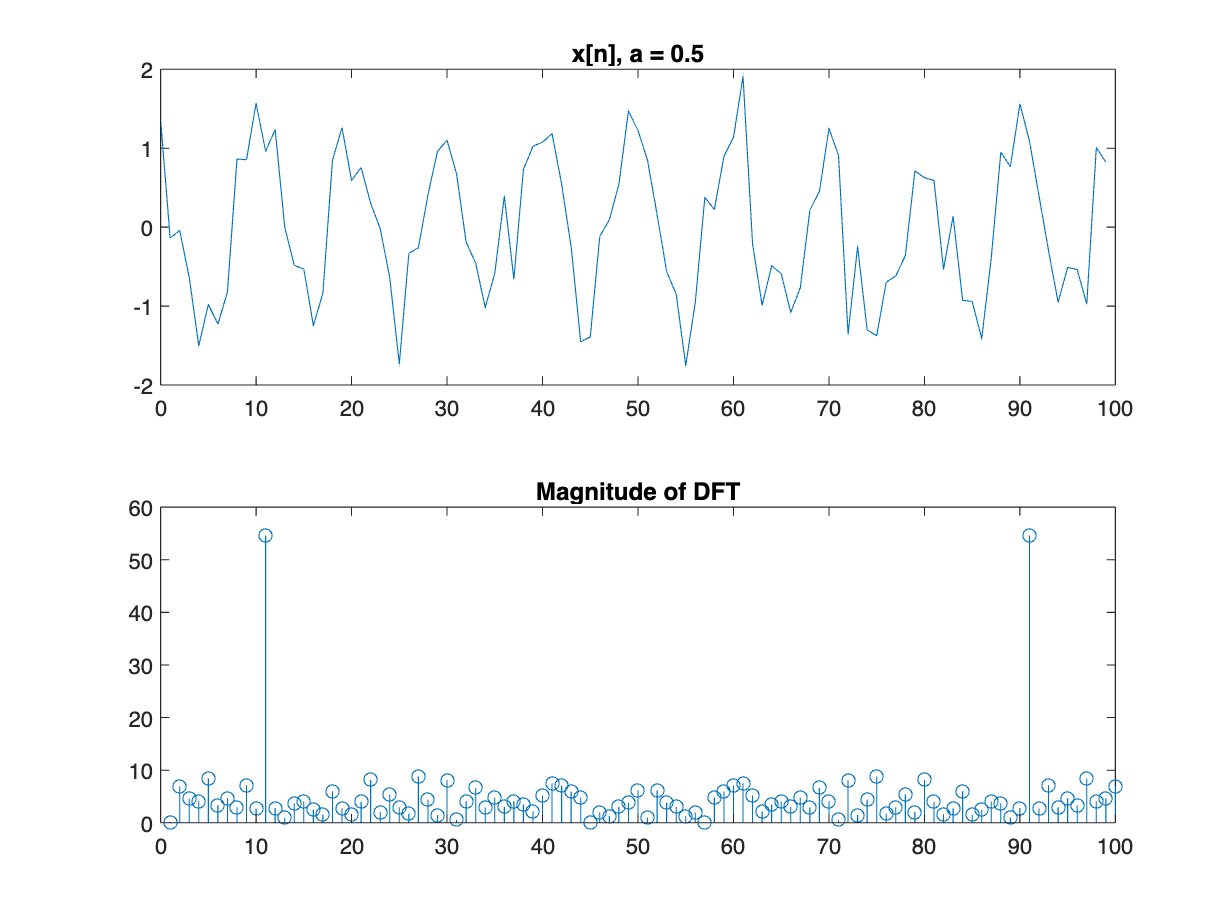

% Part c
a = 0.5;
nv = 0:(N-1);
x = cos(w0*nv) + a*randn(size(nv));

figure;
subplot(2,1,1);
plot(nv,x);
title('x[n], a = 0.5');
subplot(2,1,2);
stem(abs(fft(x)));
title('Magnitude of DFT');

**Can you see that it is a sinusoidal signal?**

    It is harder to tell but I'd still say yes, you can make out that it's sinusoidal.

**Is the value of the DFT corresponding to w0 easy to distinguish by its height relative the values at other frequencies?**

    Yes, its peak is much higher.

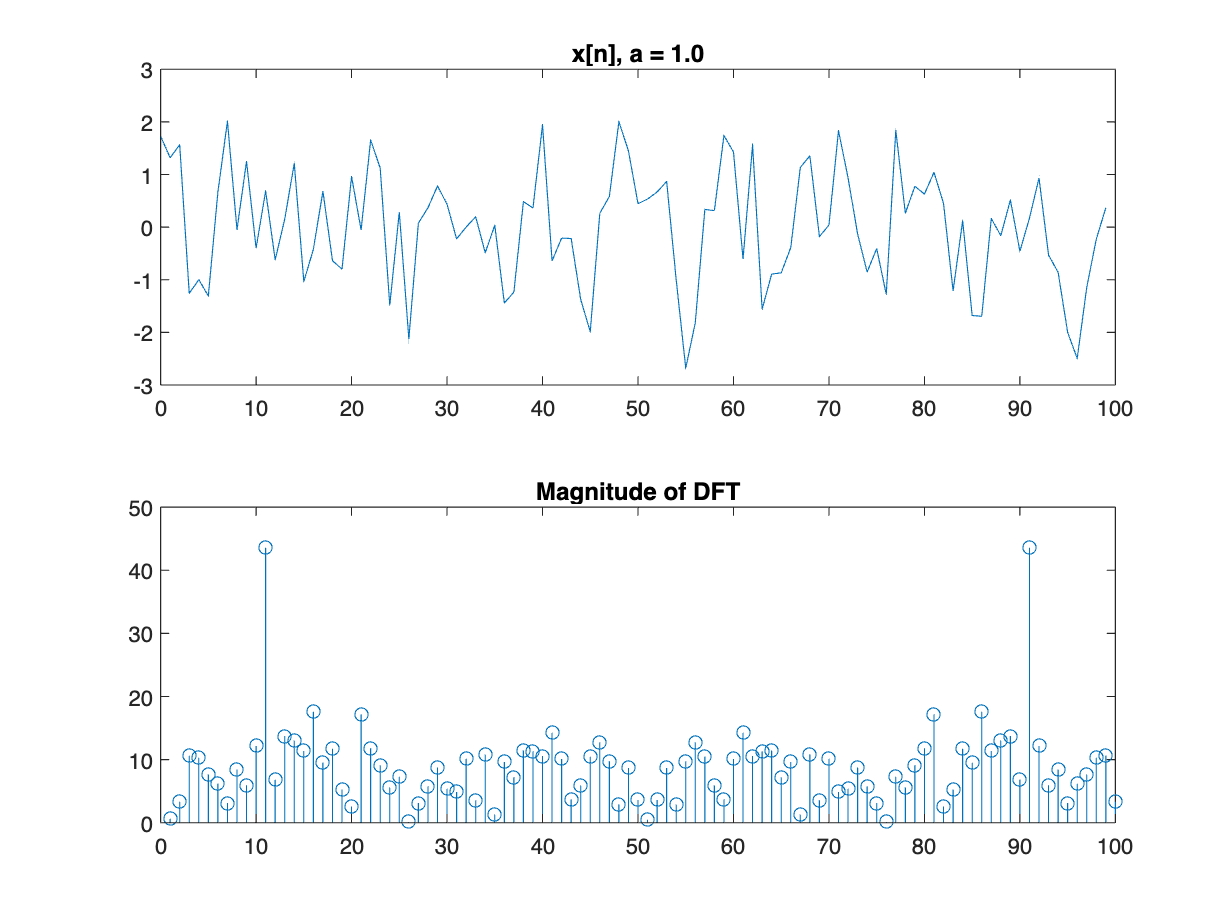

a = 1.0;
nv = 0:(N-1);
x = cos(w0*nv) + a*randn(size(nv));

figure;
subplot(2,1,1);
plot(nv,x);
title('x[n], a = 1.0');
subplot(2,1,2);
stem(abs(fft(x)));
title('Magnitude of DFT');

**Can you see that it is a sinusoidal signal?**

    At this point it would be hard to tell that it's a sinusoidal signal.

**Is the value of the DFT corresponding to w0 easy to distinguish by its height relative the values at other frequencies?**

    Yes, its peak is still slightly higher.

## Part d

**Find the highest value of a for which the time waveform, x, looks like it has a noticeable sinusoidal component.**

    a = 0.8

## Part e

**Find the highest value of a for which the DFT of x looks like it has a noticeable sinusoidal component.**

    a = 1.6

**How does it compare to the value from (d)?**

    a is higher for the DFT.

## Question 3

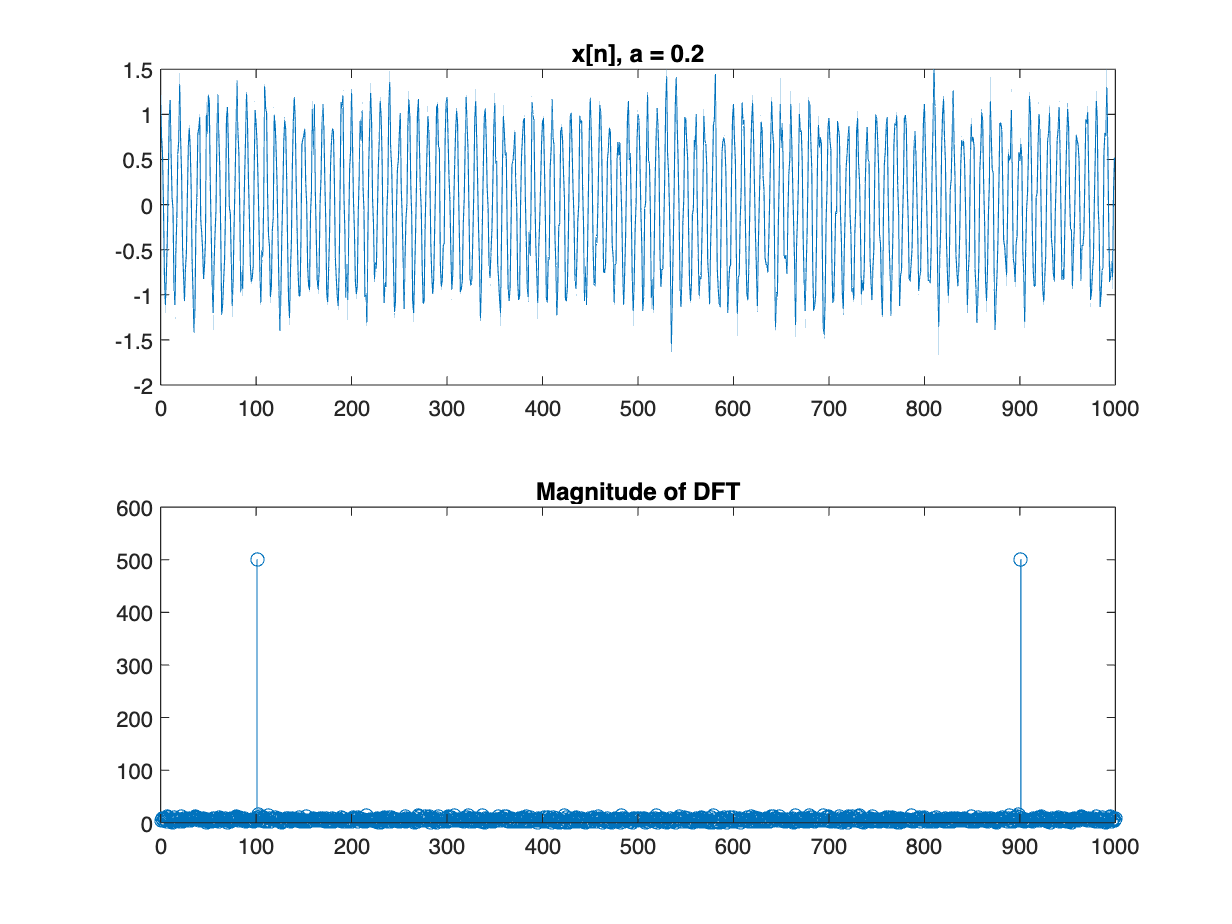

% Part a + b
N = 1000;
w0 = 0.2*pi;
a = 0.2;
nv = 0:(N-1);
x = cos(w0*nv) + a*randn(size(nv));

figure;
subplot(2,1,1);
plot(nv,x);
title('x[n], a = 0.2');
subplot(2,1,2);
stem(abs(fft(x)));
title('Magnitude of DFT');

**Can you see that it is a sinusoidal signal?**

    It is somewhat squished on the graph, but when zooming in it is obvious.

**Is the value of the DFT corresponding to w0 easy to distinguish by its height relative the values at other frequencies?**

    Yes, its peak is much higher.

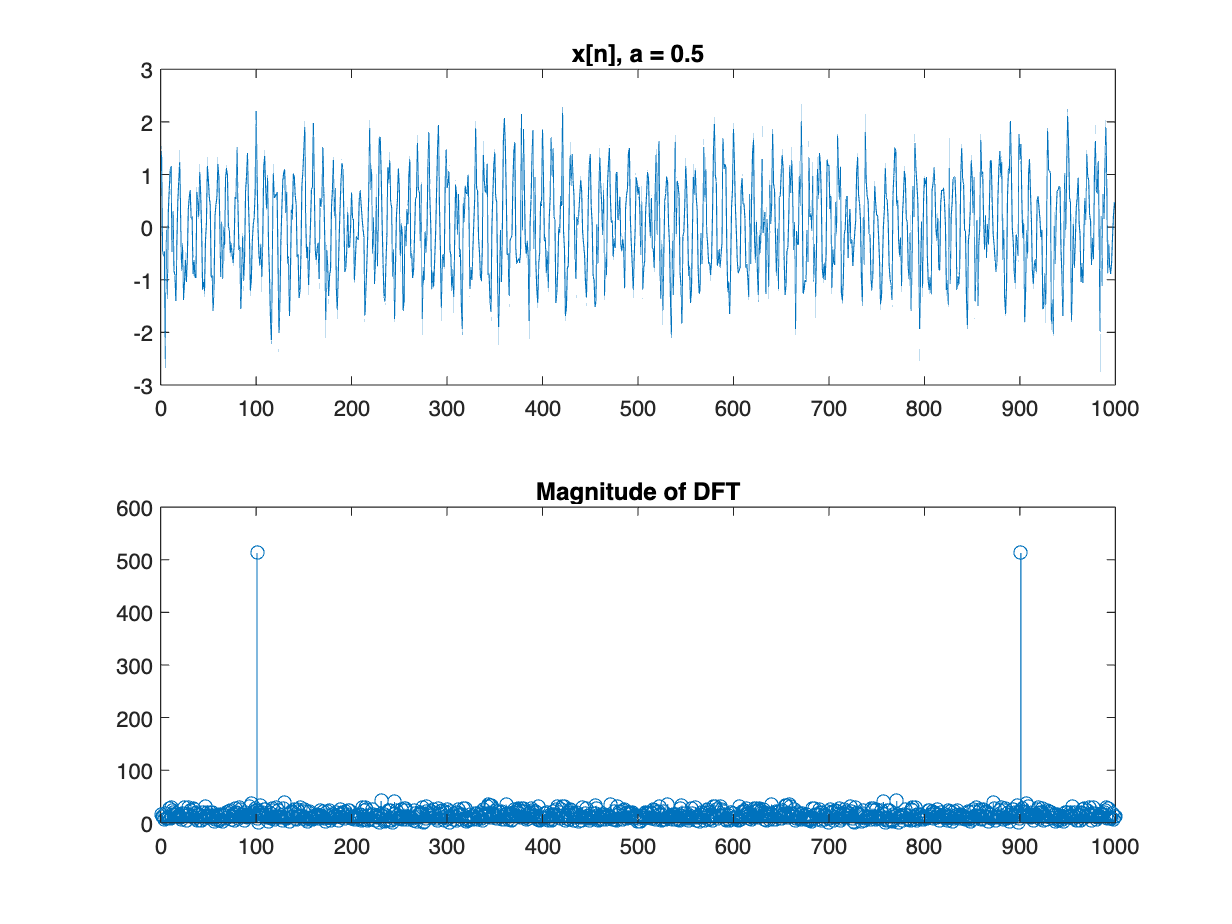

% Part c
a = 0.5;
nv = 0:(N-1);
x = cos(w0*nv) + a*randn(size(nv));

figure;
subplot(2,1,1);
plot(nv,x);
title('x[n], a = 0.5');
subplot(2,1,2);
stem(abs(fft(x)));
title('Magnitude of DFT');

**Can you see that it is a sinusoidal signal?**

    A bit noiser, but still obvious.

**Is the value of the DFT corresponding to w0 easy to distinguish by its height relative the values at other frequencies?**

    Yes, its peak is much higher.

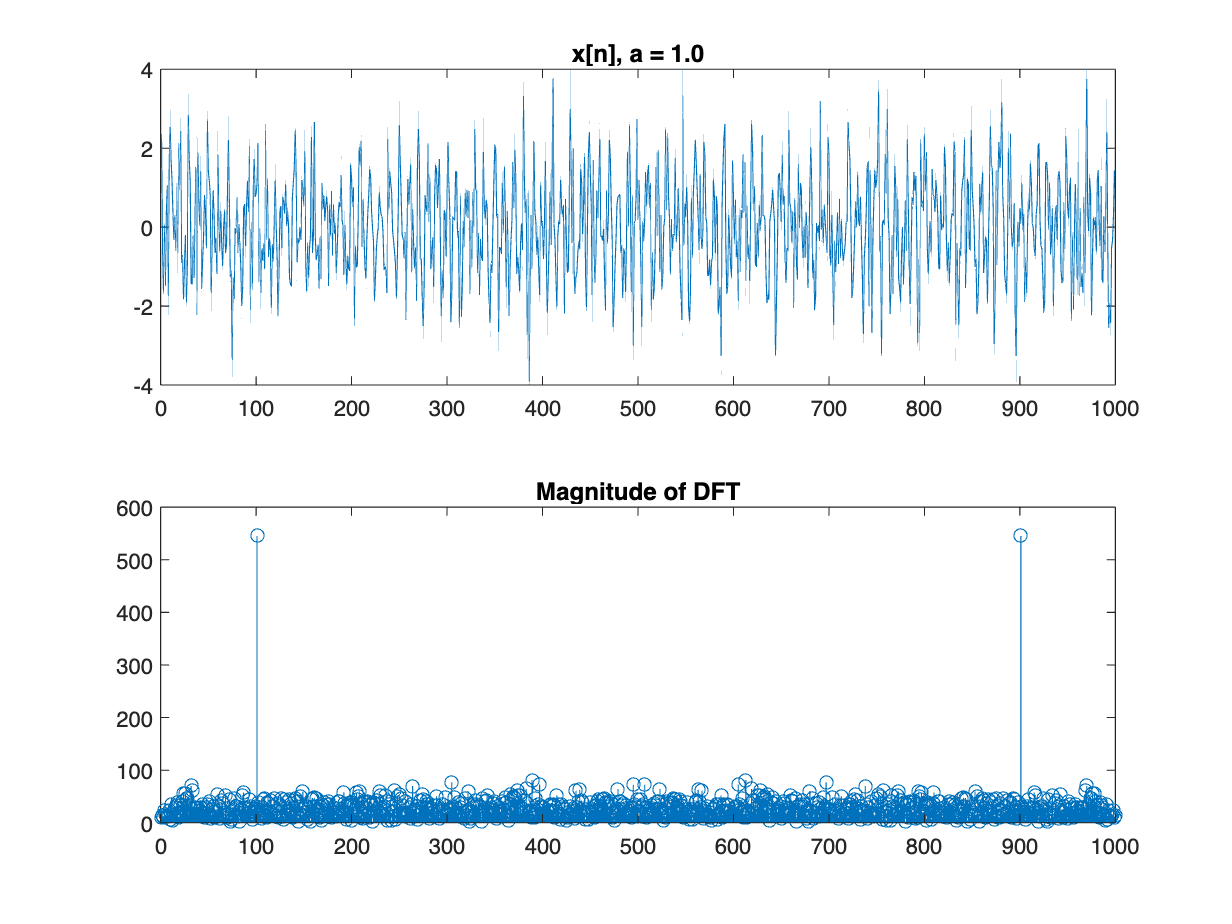

a = 1.0;
nv = 0:(N-1);
x = cos(w0*nv) + a*randn(size(nv));

figure;
subplot(2,1,1);
plot(nv,x);
title('x[n], a = 1.0');
subplot(2,1,2);
stem(abs(fft(x)));
title('Magnitude of DFT');

**Can you see that it is a sinusoidal signal?**

    Very noisy, not as obvious.

**Is the value of the DFT corresponding to w0 easy to distinguish by its height relative the values at other frequencies?**

    Yes, its peak is much higher.

## Part d

**Find the highest value of a for which the time waveform, x, looks like it has a noticeable sinusoidal component.**

    a = 1.2

## Part e

**Find the highest value of a for which the DFT of x looks like it has a noticeable sinusoidal component.**

    a = 3.0

**How does it compare to the value from (d)?**

    a can be much higher for the DFT.

## Question 4

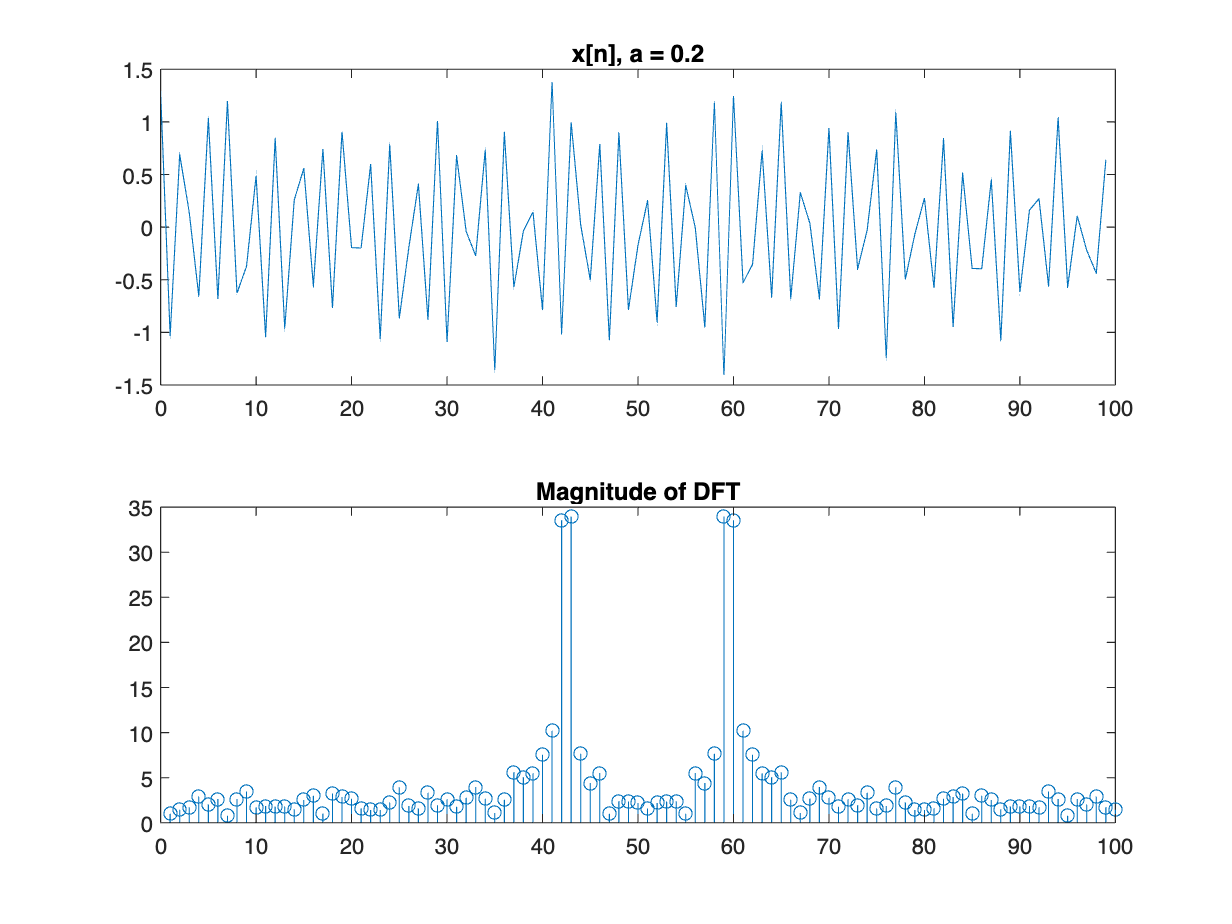

% Part a + b
N = 100;
w0 = 0.83*pi;
a = 0.2;
nv = 0:(N-1);
x = cos(w0*nv) + a*randn(size(nv));

figure;
subplot(2,1,1);
plot(nv,x);
title('x[n], a = 0.2');
subplot(2,1,2);
stem(abs(fft(x)));
title('Magnitude of DFT');

**Can you see that it is a sinusoidal signal?**

    A little noisy to start, but still obvious.

**Is the value of the DFT corresponding to w0 easy to distinguish by its height relative the values at other frequencies?**

    Yes, its peak is much higher.

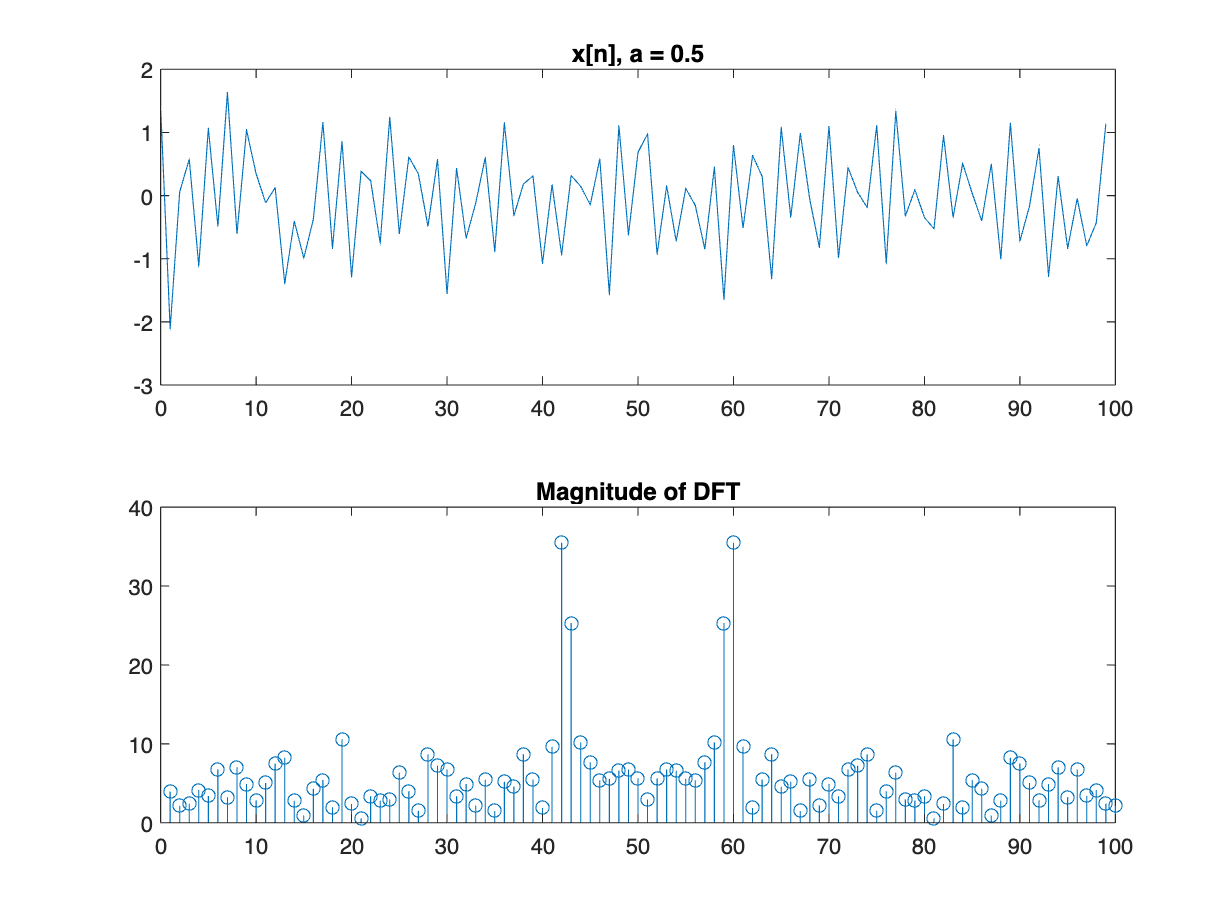

% Part c
a = 0.5;
nv = 0:(N-1);
x = cos(w0*nv) + a*randn(size(nv));

figure;
subplot(2,1,1);
plot(nv,x);
title('x[n], a = 0.5');
subplot(2,1,2);
stem(abs(fft(x)));
title('Magnitude of DFT');

**Can you see that it is a sinusoidal signal?**

    Bordering the line between sinusoidal signal or not.

**Is the value of the DFT corresponding to w0 easy to distinguish by its height relative the values at other frequencies?**

    Yes, its peak is much higher.

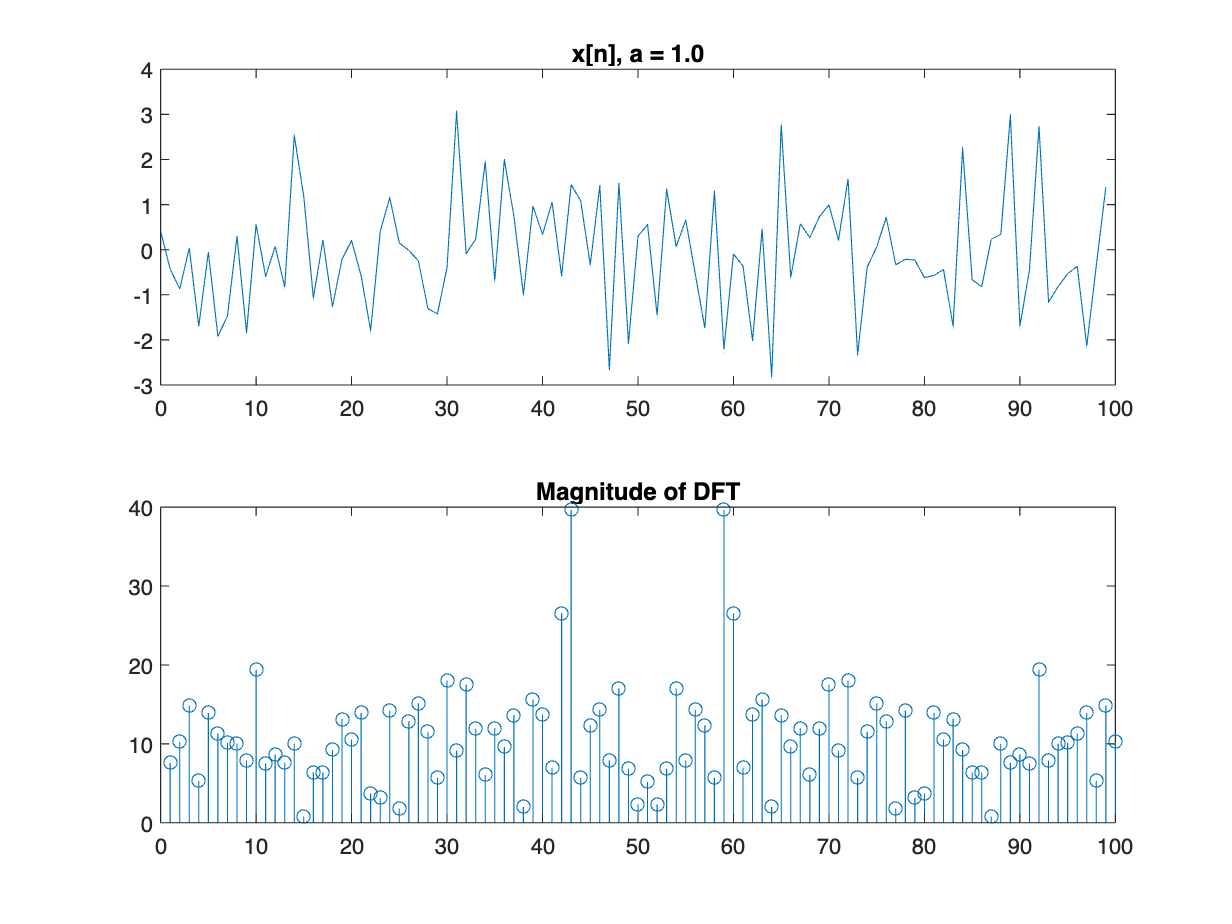

a = 1.0;
nv = 0:(N-1);
x = cos(w0*nv) + a*randn(size(nv));

figure;
subplot(2,1,1);
plot(nv,x);
title('x[n], a = 1.0');
subplot(2,1,2);
stem(abs(fft(x)));
title('Magnitude of DFT');

**Can you see that it is a sinusoidal signal?**

    No, it is not obvious that it is a sinusoidal signal.

**Is the value of the DFT corresponding to w0 easy to distinguish by its height relative the values at other frequencies?**

    Yes, its peak is much higher.

## Part d

**Find the highest value of a for which the time waveform, x, looks like it has a noticeable sinusoidal component.**

    a = 0.5

## Part e

**Find the highest value of a for which the DFT of x looks like it has a noticeable sinusoidal component.**

    a = 1.5

**How does it compare to the value from (d)?**

    Again, a for the DFT can be much higher.

## Question 5

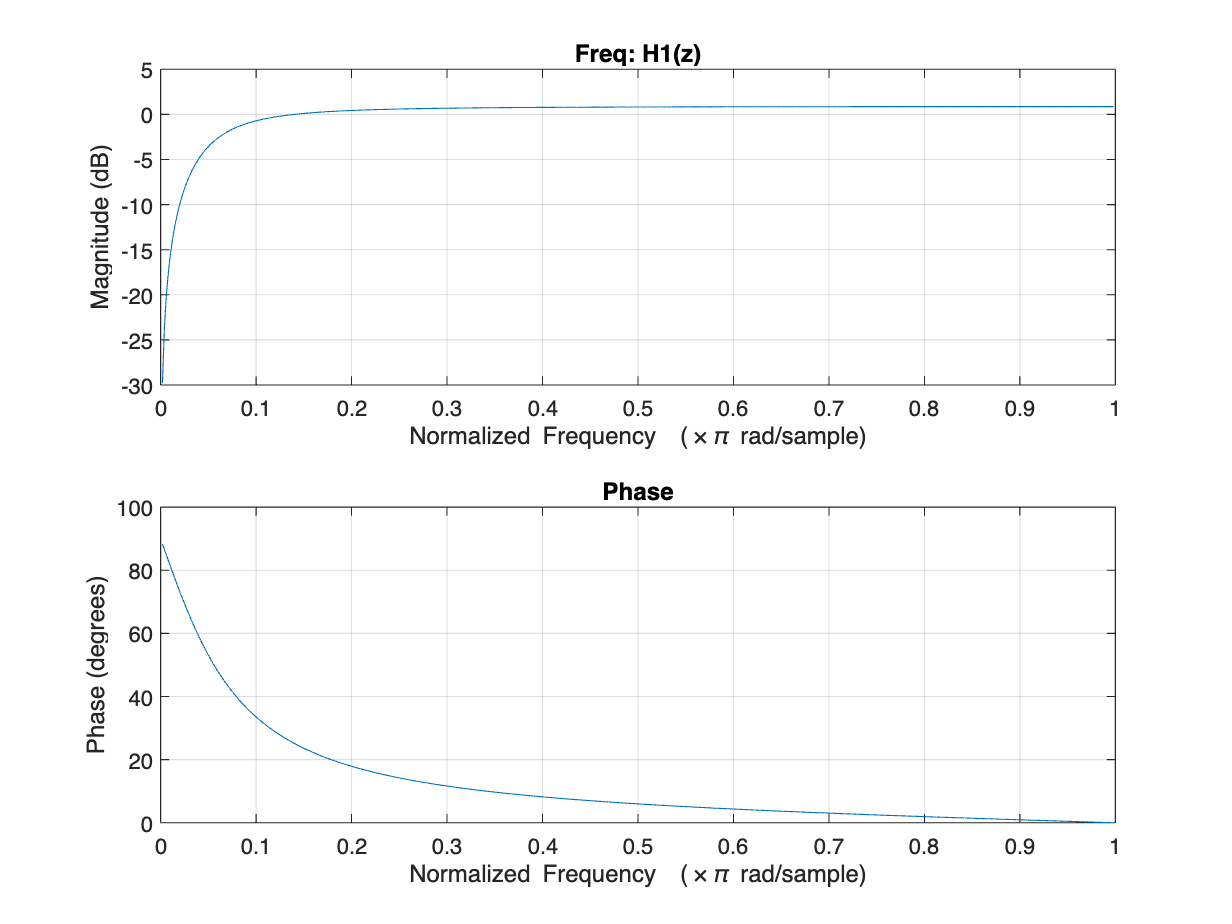

% Part a
syms z;
H1 = (z - 1)/(z - 0.81);
H2 = (z + 1)/(z - 0.81);

[num, den] = numden(H1);
b = sym2poly(num);
a = sym2poly(den);

figure;
subplot(1,2,1);
freqz(b, a, 512);
title('Freq: H1(z)');

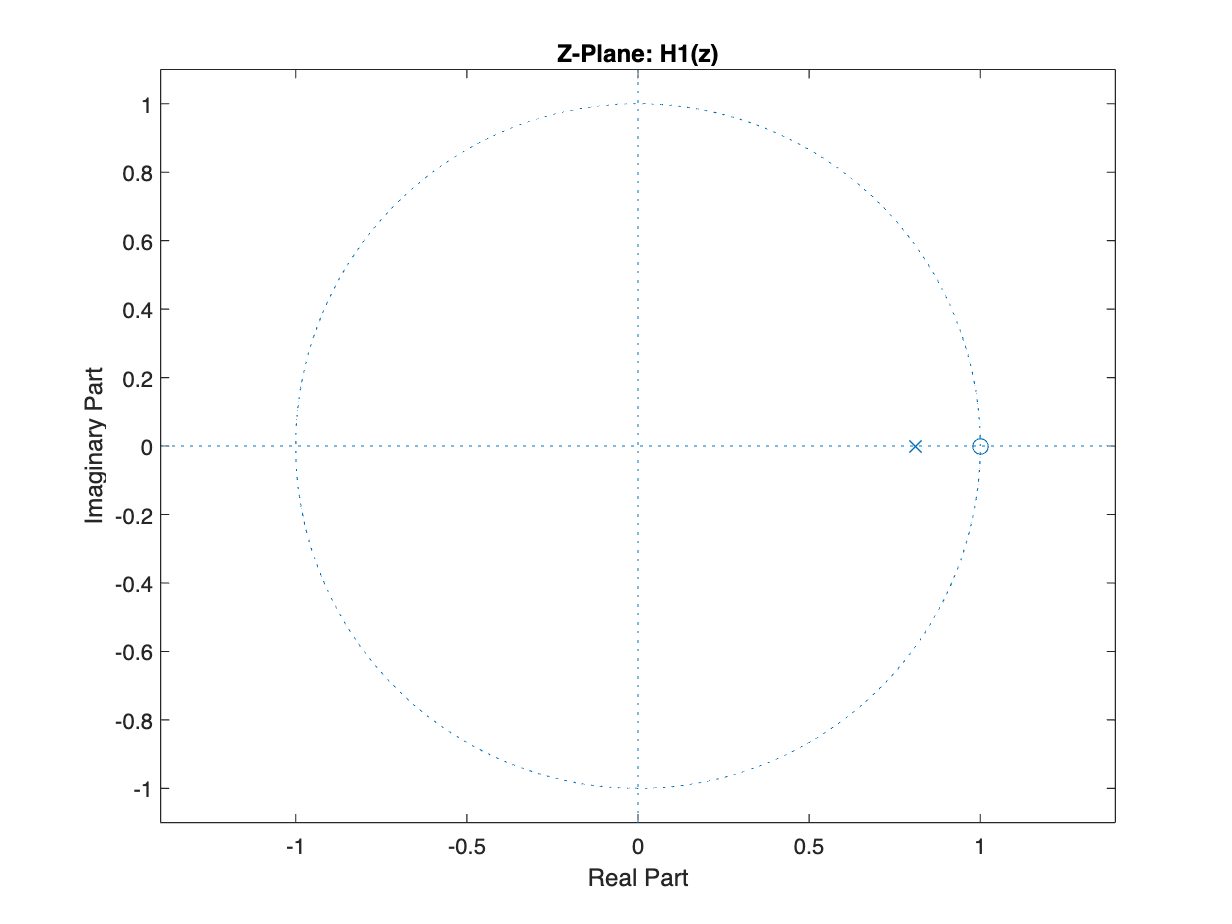

figure;
zplane(b, a);
title('Z-Plane: H1(z)');

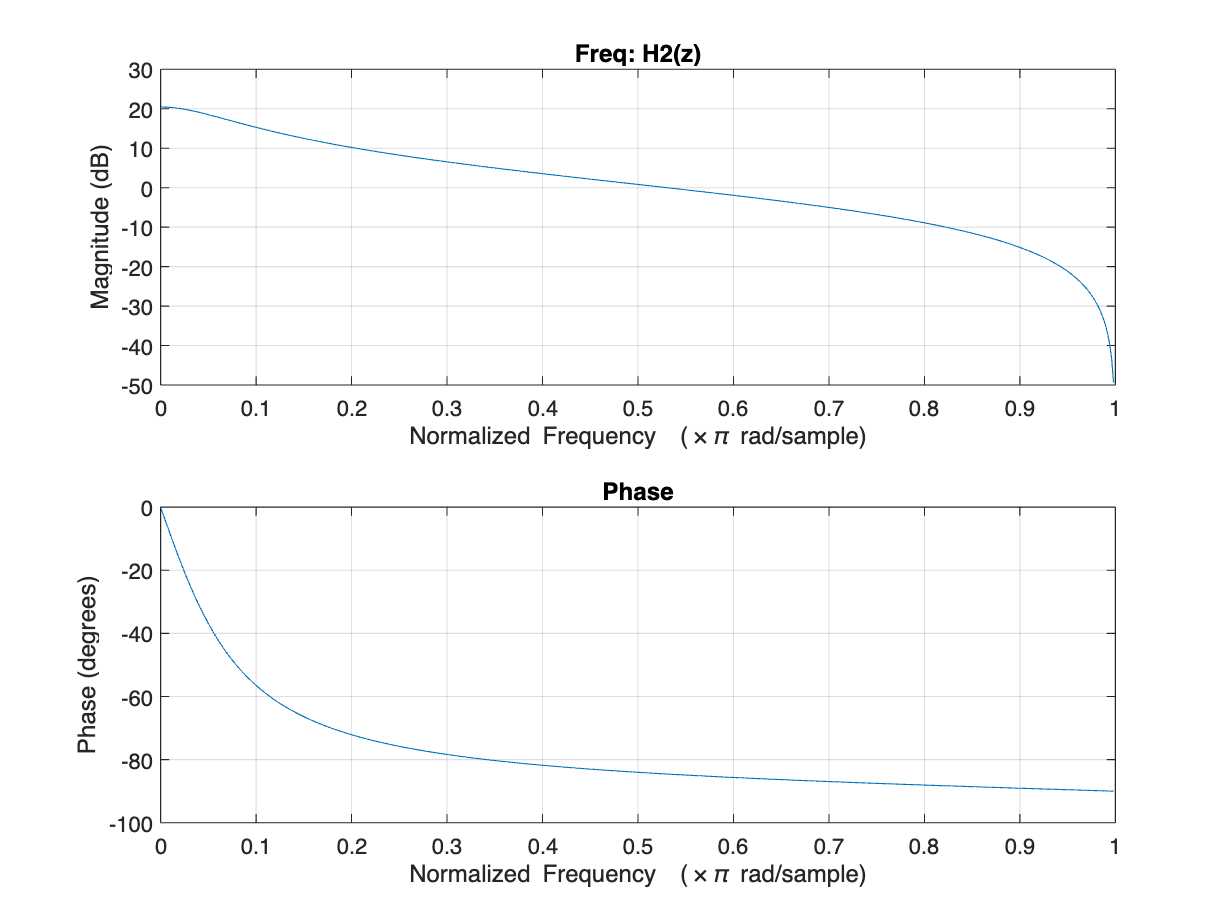

[num, den] = numden(H2);
b = sym2poly(num);
a = sym2poly(den);

figure;
subplot(1,2,1);
freqz(b, a, 512);
title('Freq: H2(z)');

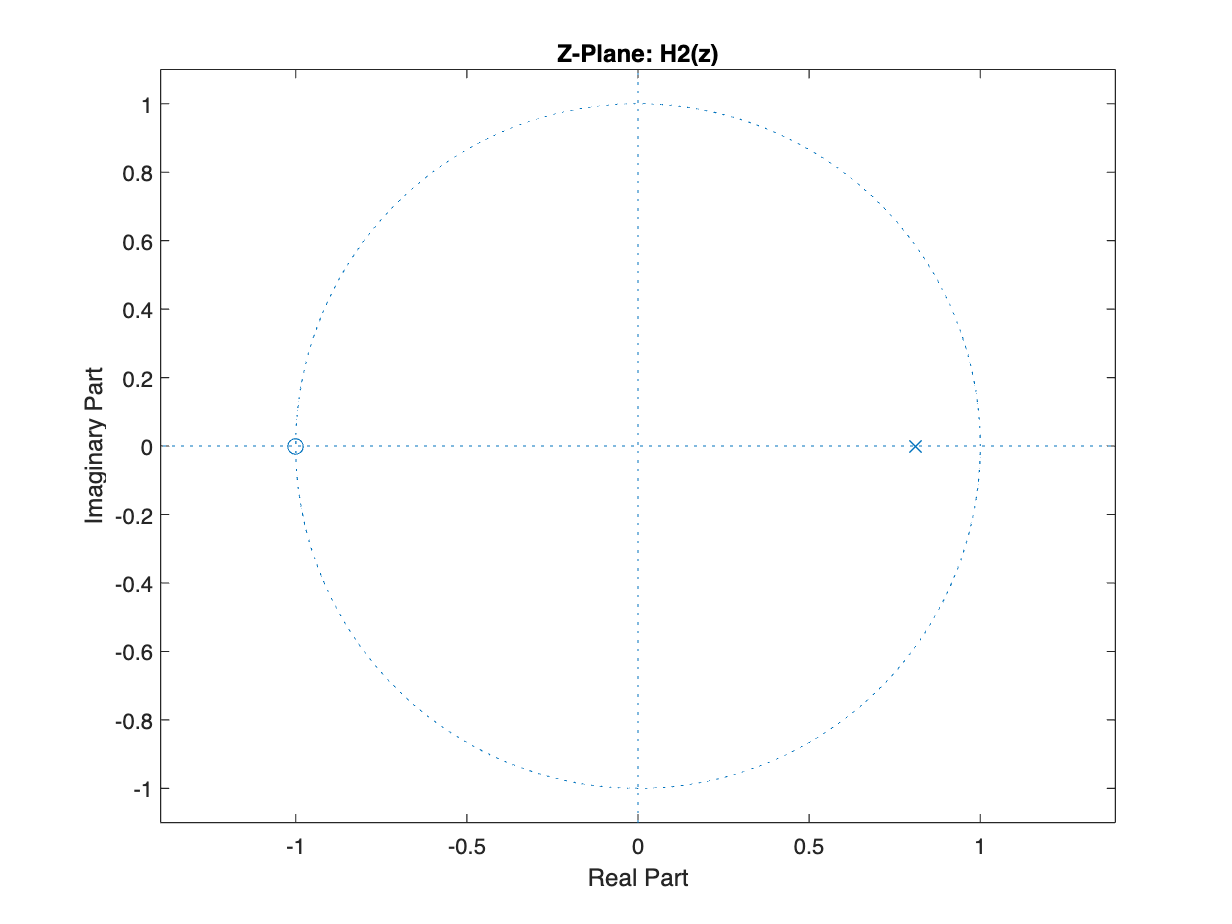

figure;
zplane(b, a);
title('Z-Plane: H2(z)');

**Find the poles and zeros of the new filters and explain how they are related to the poles and zeros of the original filters.**

    Zeros (H1): z = 1

    Poles (H1): z = 0.81

    Zeros (H2): z = -1

    Poles (H2): z = 0.81

**What kind of filter is each of the new filters?**

    H1: Notch

    H2: Butterworth

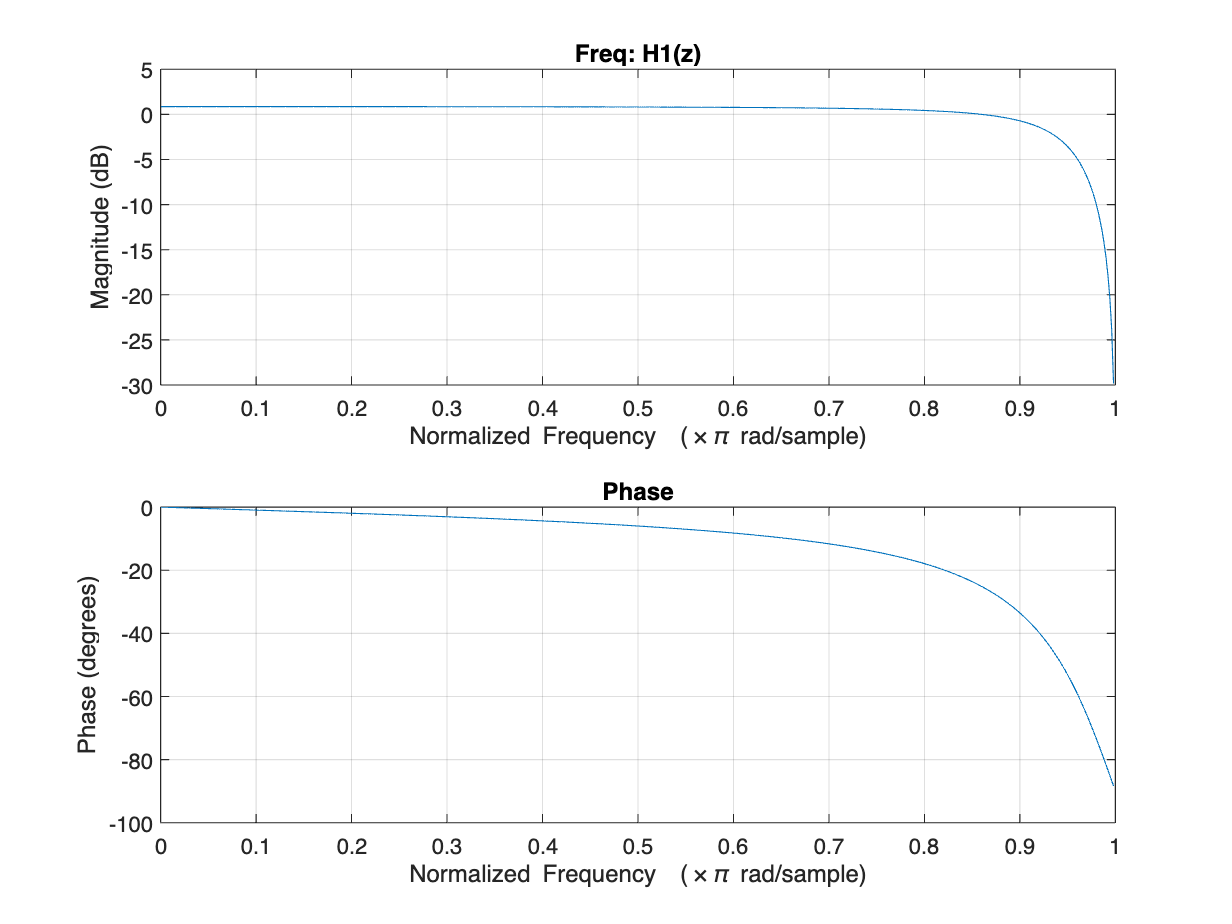

% Part b
syms z;
H1 = (-z - 1)/(-z - 0.81);
H2 = (-z + 1)/(-z - 0.81);

[num, den] = numden(H1);
b = sym2poly(num);
a = sym2poly(den);

figure;
subplot(1,2,1);
freqz(b, a, 512);
title('Freq: H1(z)');

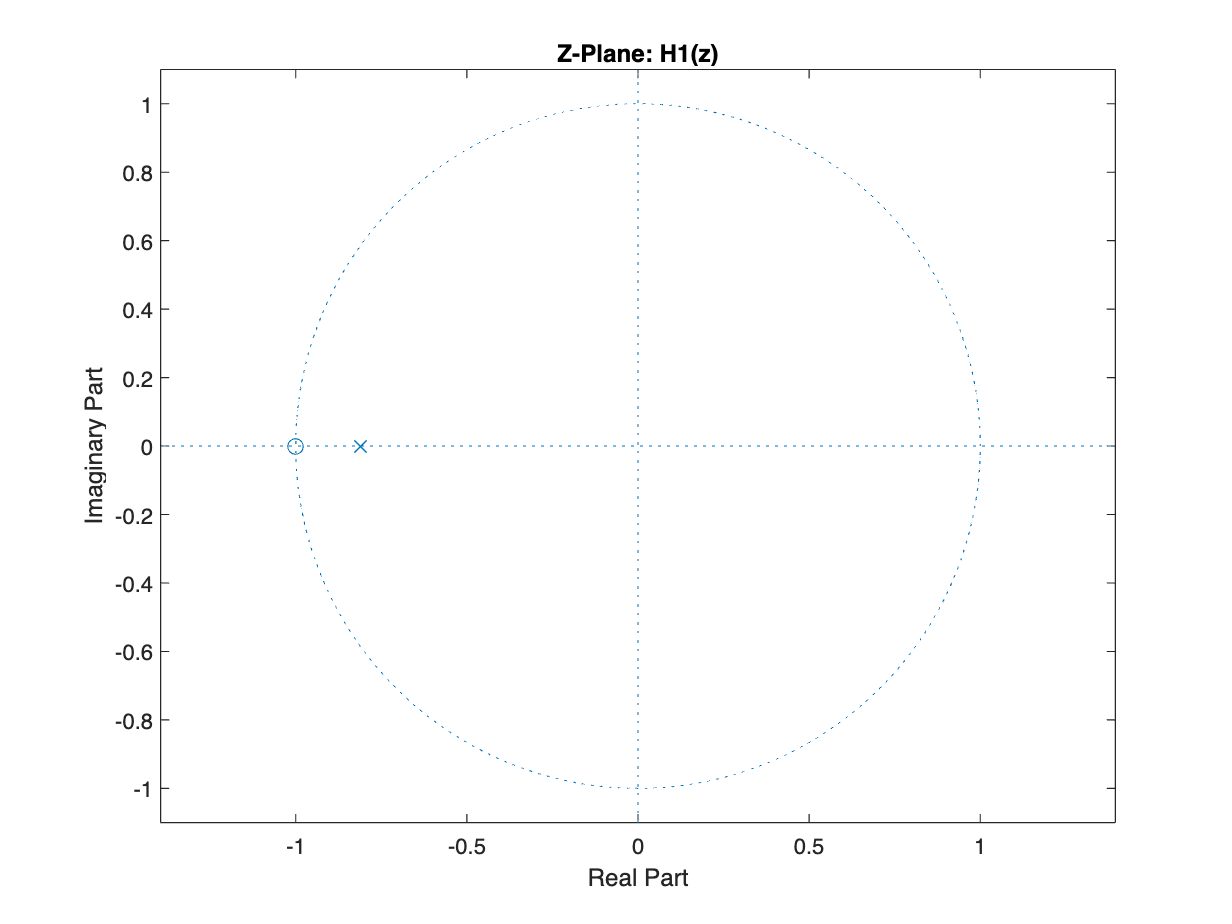

figure;
zplane(b, a);
title('Z-Plane: H1(z)');

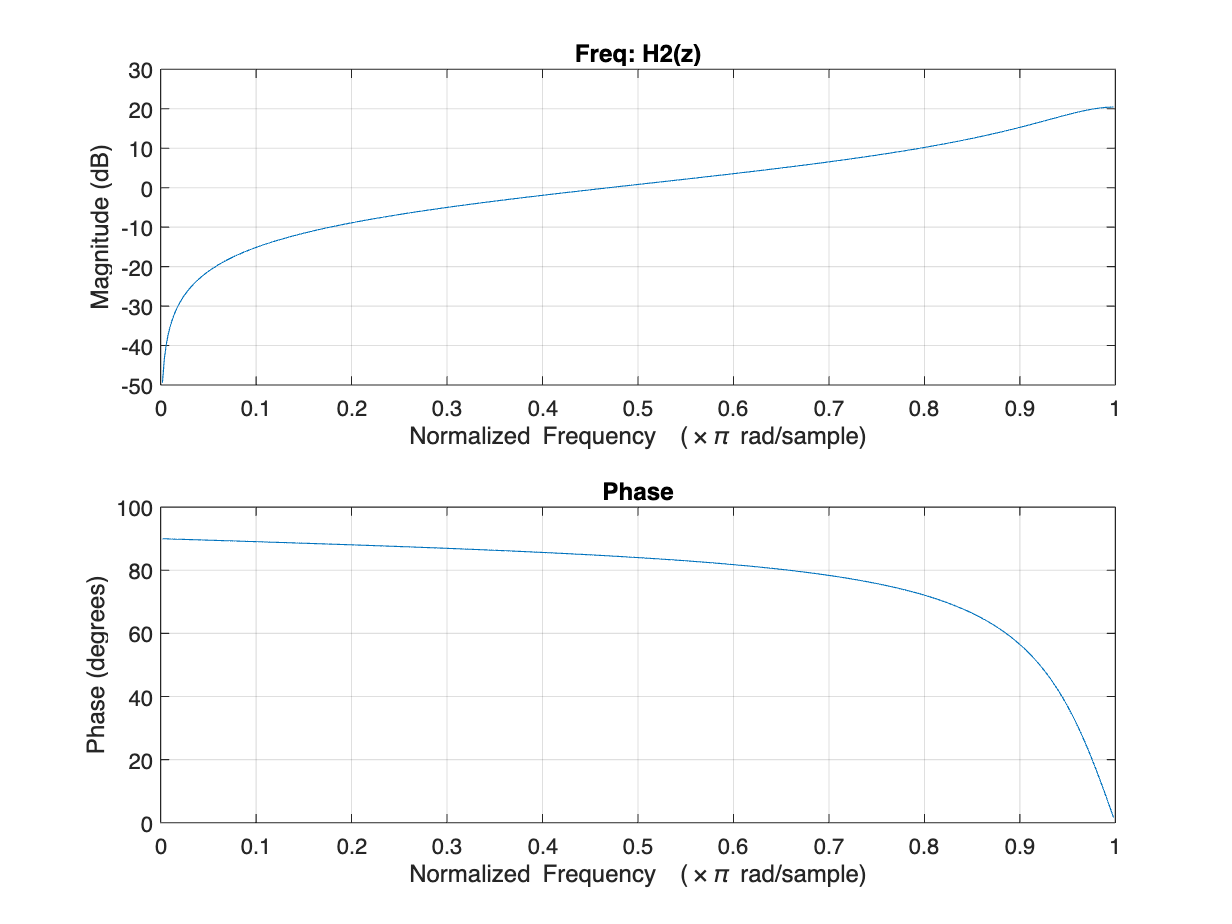

[num, den] = numden(H2);
b = sym2poly(num);
a = sym2poly(den);

figure;
subplot(1,2,1);
freqz(b, a, 512);
title('Freq: H2(z)');

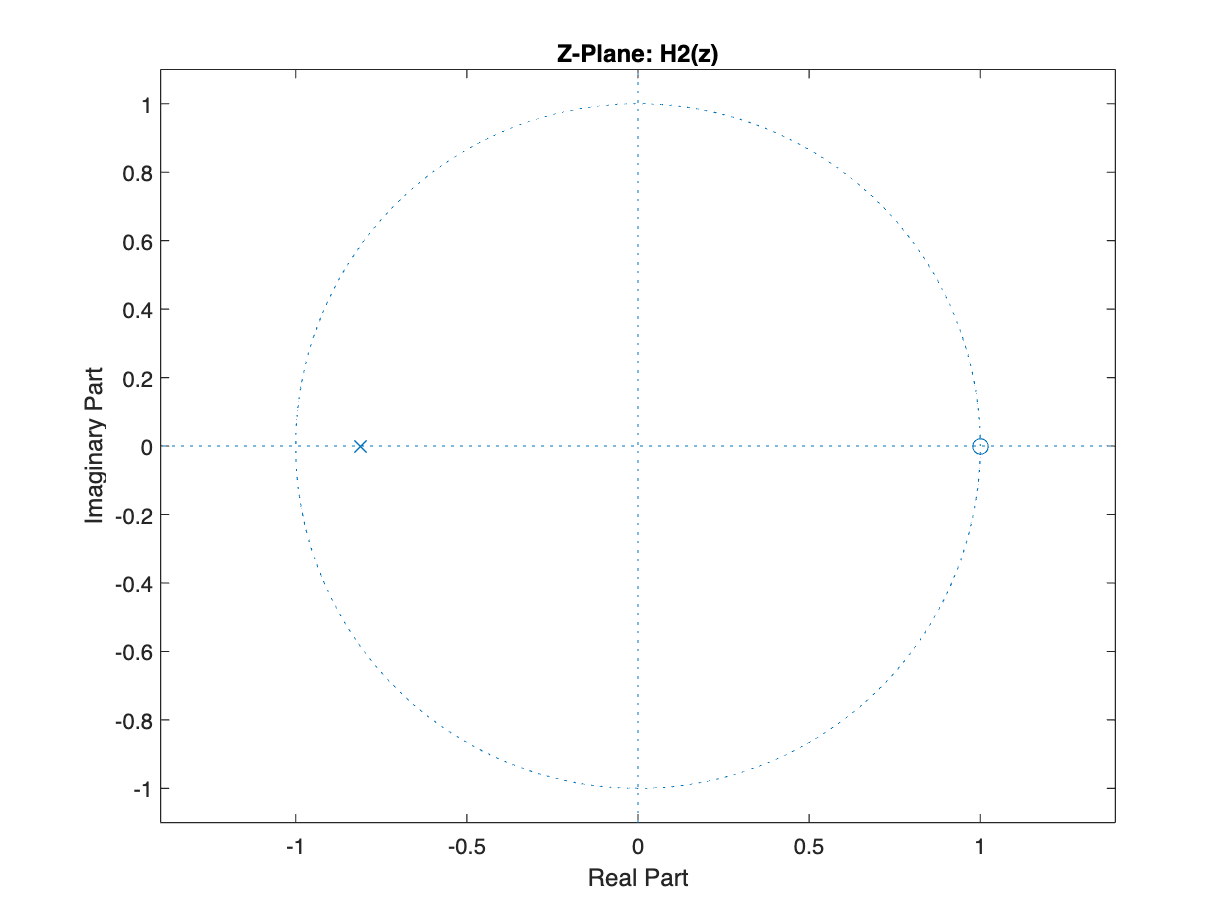

figure;
zplane(b, a);
title('Z-Plane: H2(z)');

**Find the poles and zeros of the new filters and explain how they are related to the poles and zeros of the original filters.**

    Zeros (H1): z = -1

    Poles (H1): z = -0.81

    Zeros (H2): z = 1

    Poles (H2): z = -0.81

**What kind of filter is each of the new filters?**

    H1: Low Pass

    H2: High Pass

## Question 6

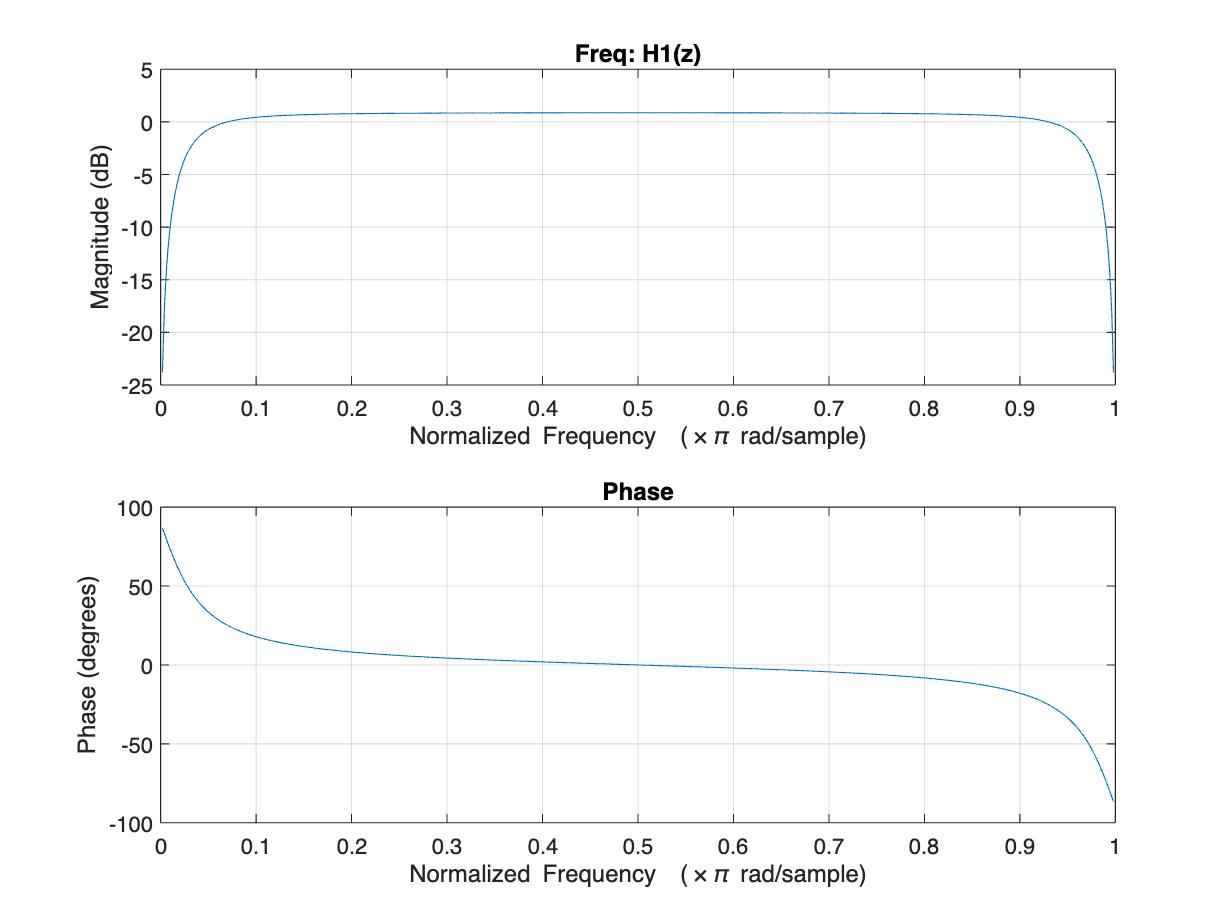

% Part a
syms z;
H1 = (z^2 - 1)/(z^2 - 0.81);
H2 = (z^2 + 1)/(z^2 - 0.81);

[num, den] = numden(H1);
b = sym2poly(num);
a = sym2poly(den);

figure;
subplot(1,2,1);
freqz(b, a, 512);
title('Freq: H1(z)');

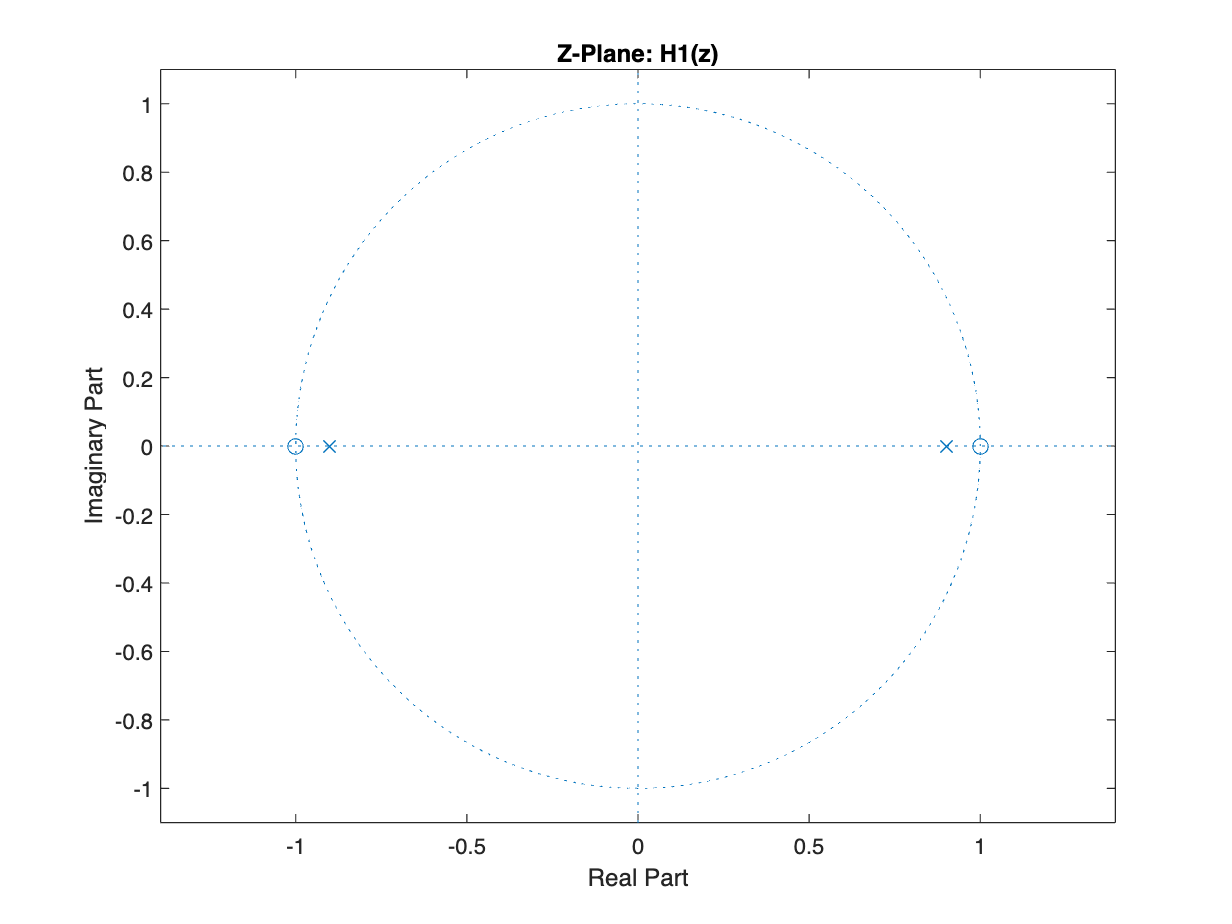

figure;
zplane(b, a);
title('Z-Plane: H1(z)');

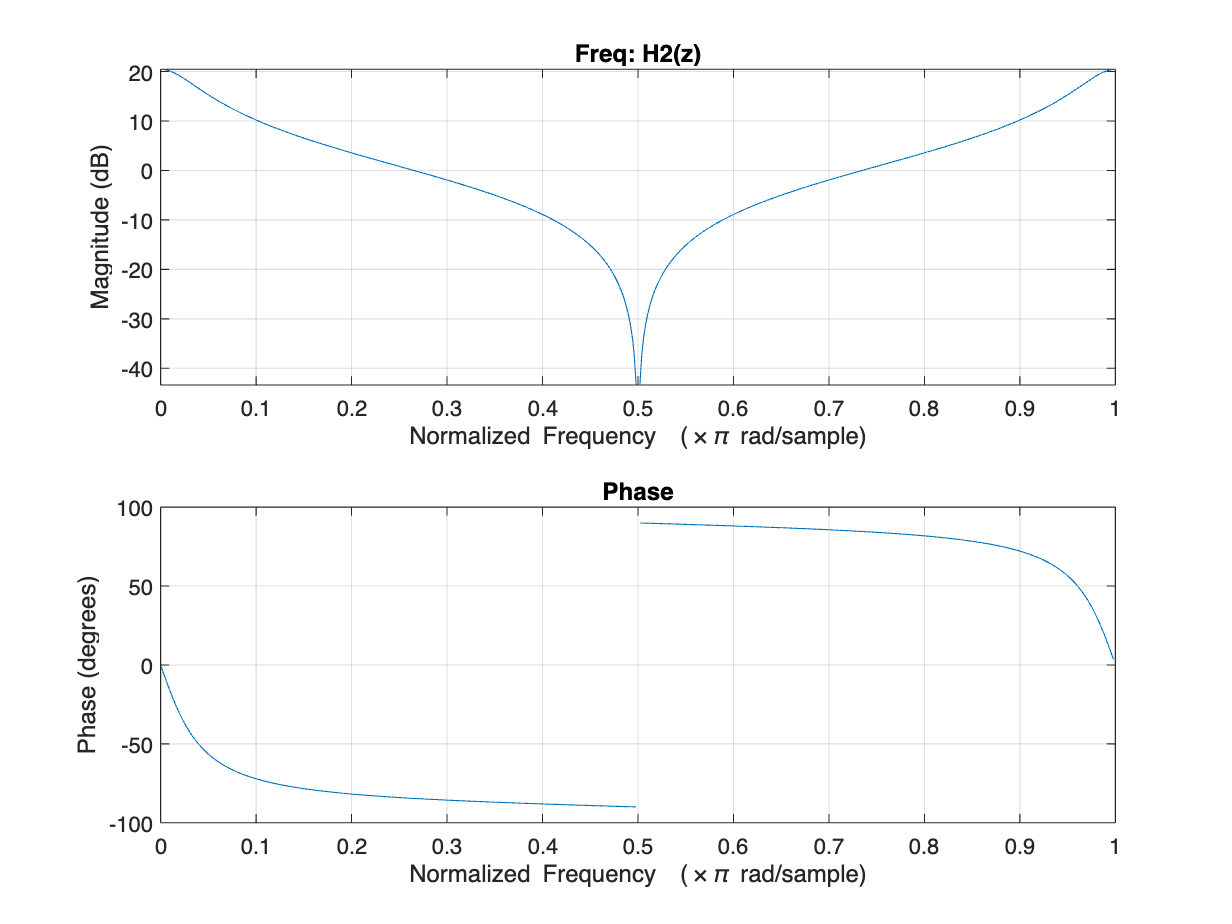

[num, den] = numden(H2);
b = sym2poly(num);
a = sym2poly(den);

figure;
subplot(1,2,1);
freqz(b, a, 512);
title('Freq: H2(z)');

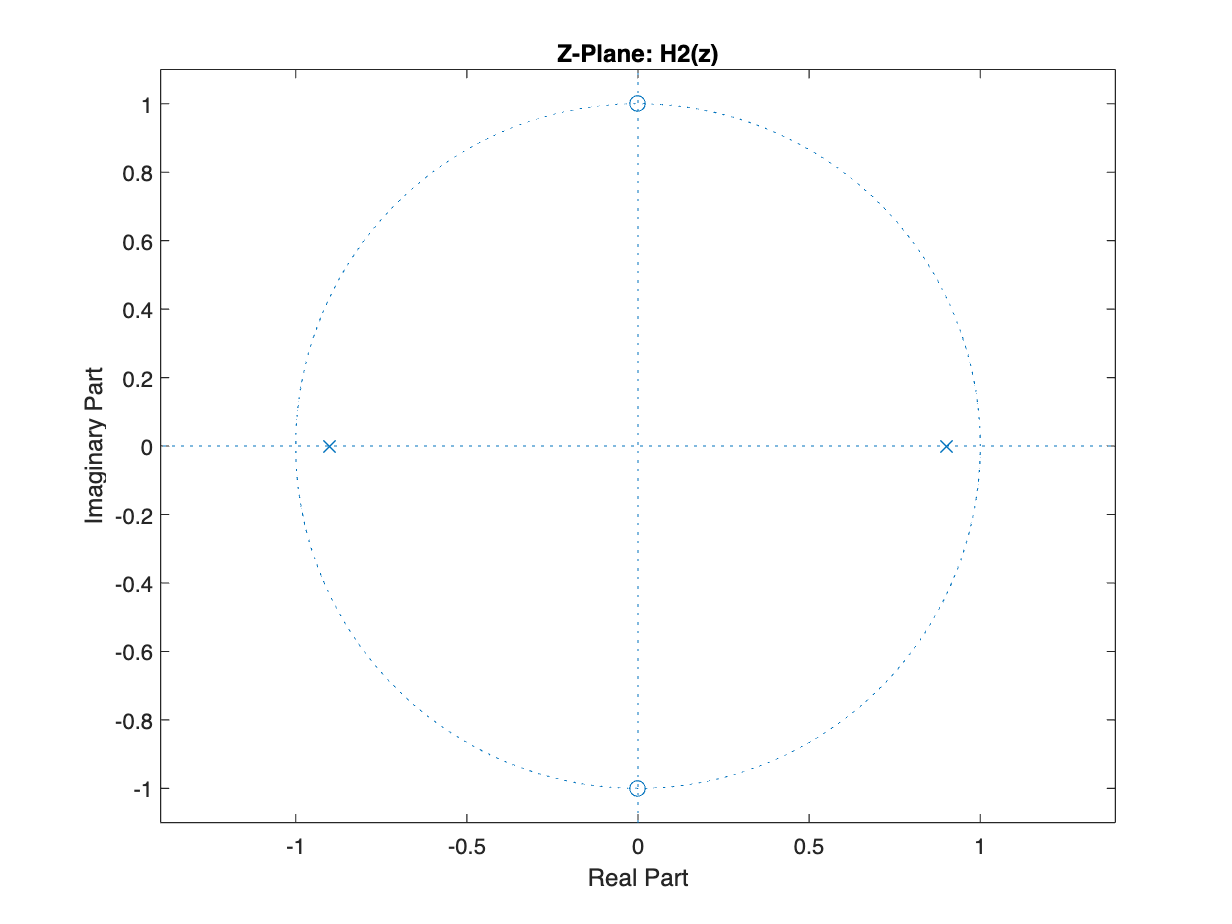

figure;
zplane(b, a);
title('Z-Plane: H2(z)');

**Find the poles and zeros of the new filters and explain how they are related to the poles and zeros of the original filters.**

    Zeros (H1): z = -1, 1

    Poles (H1): z = -0.9, 0.9

    Zeros (H2): z = -j, j

    Poles (H2): z = -0.9, 0.9

**What kind of filter is each of the new filters?**

    H1: Band Pass

    H2: Band-stop

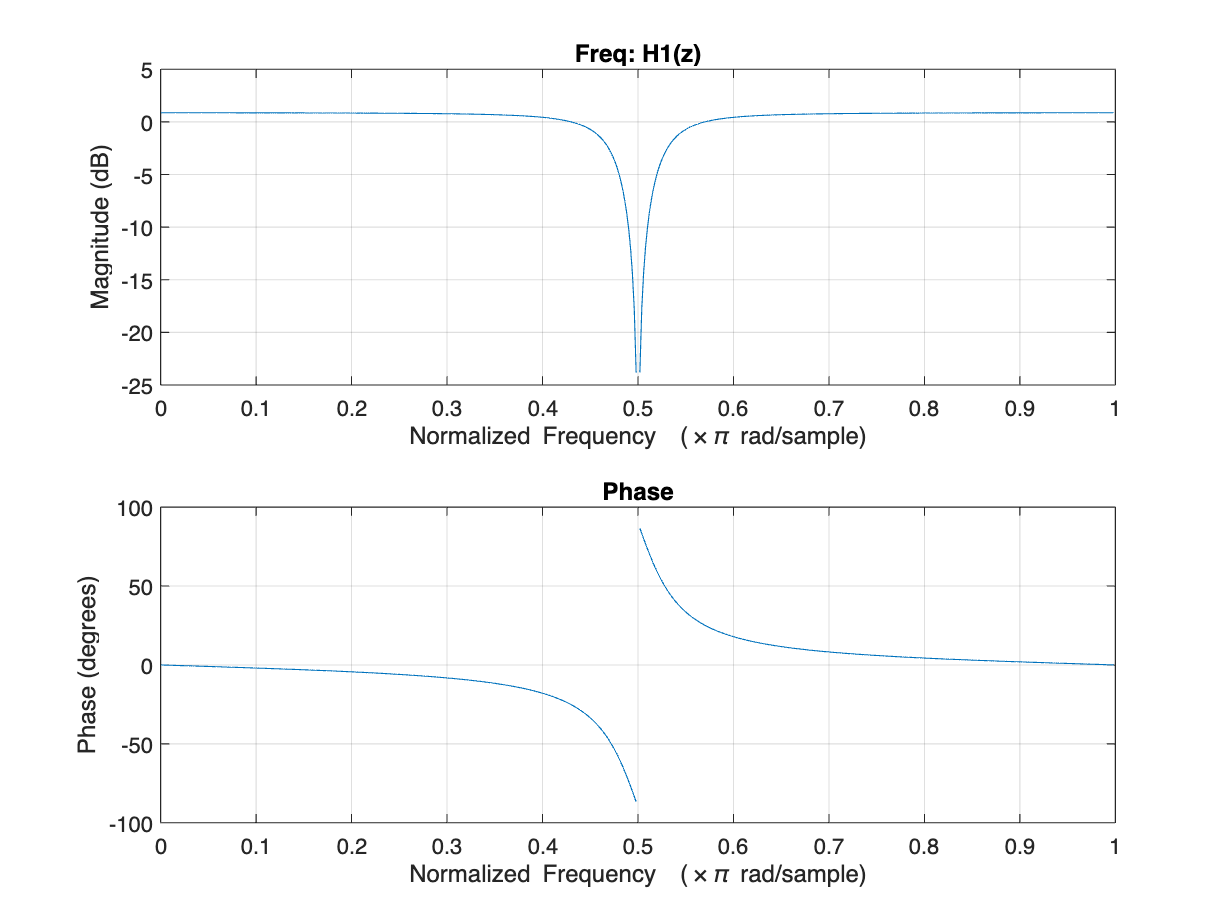

% Part b
syms z;
H1 = (-z^2 - 1)/(-z^2 - 0.81);
H2 = (-z^2 + 1)/(-z^2 - 0.81);

[num, den] = numden(H1);
b = sym2poly(num);
a = sym2poly(den);

figure;
subplot(1,2,1);
freqz(b, a, 512);
title('Freq: H1(z)');

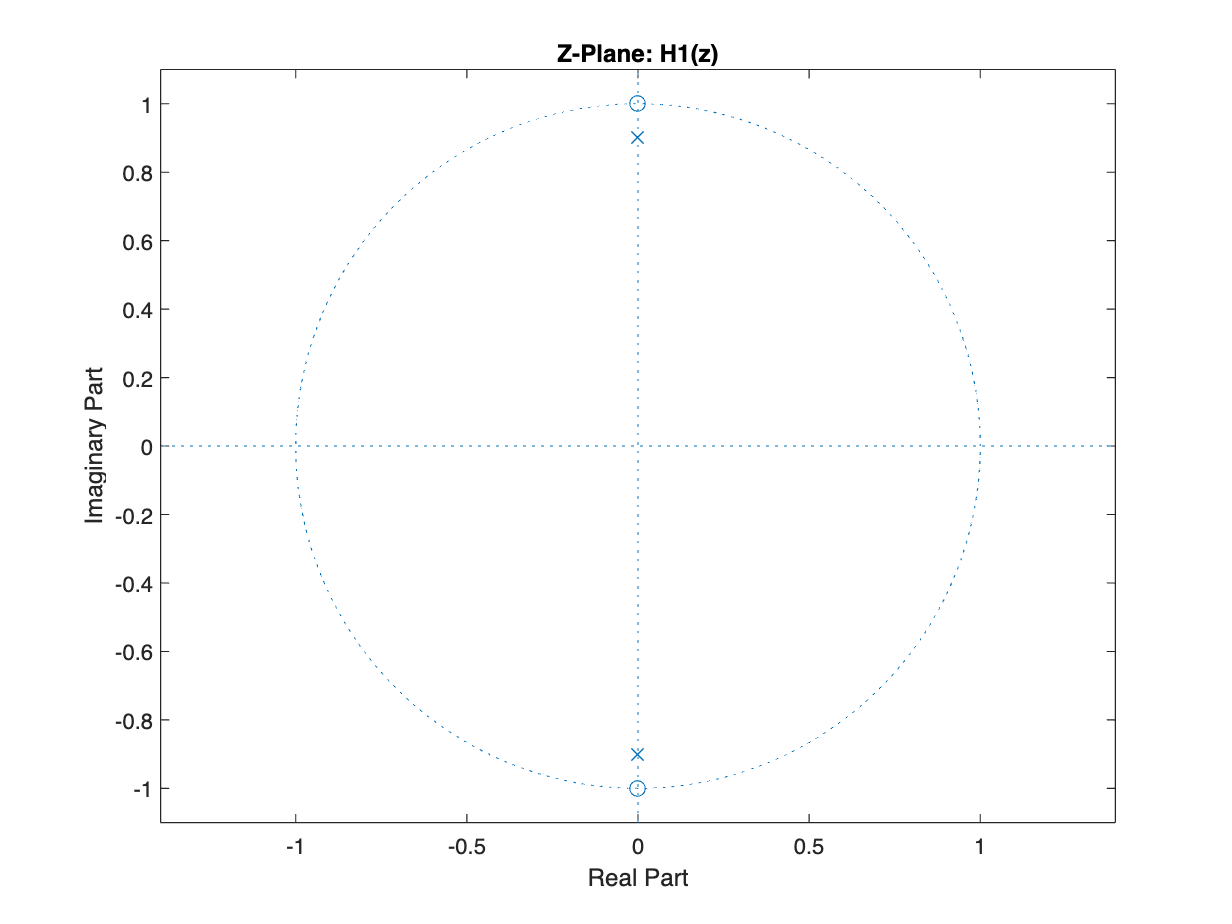

figure;
zplane(b, a);
title('Z-Plane: H1(z)');

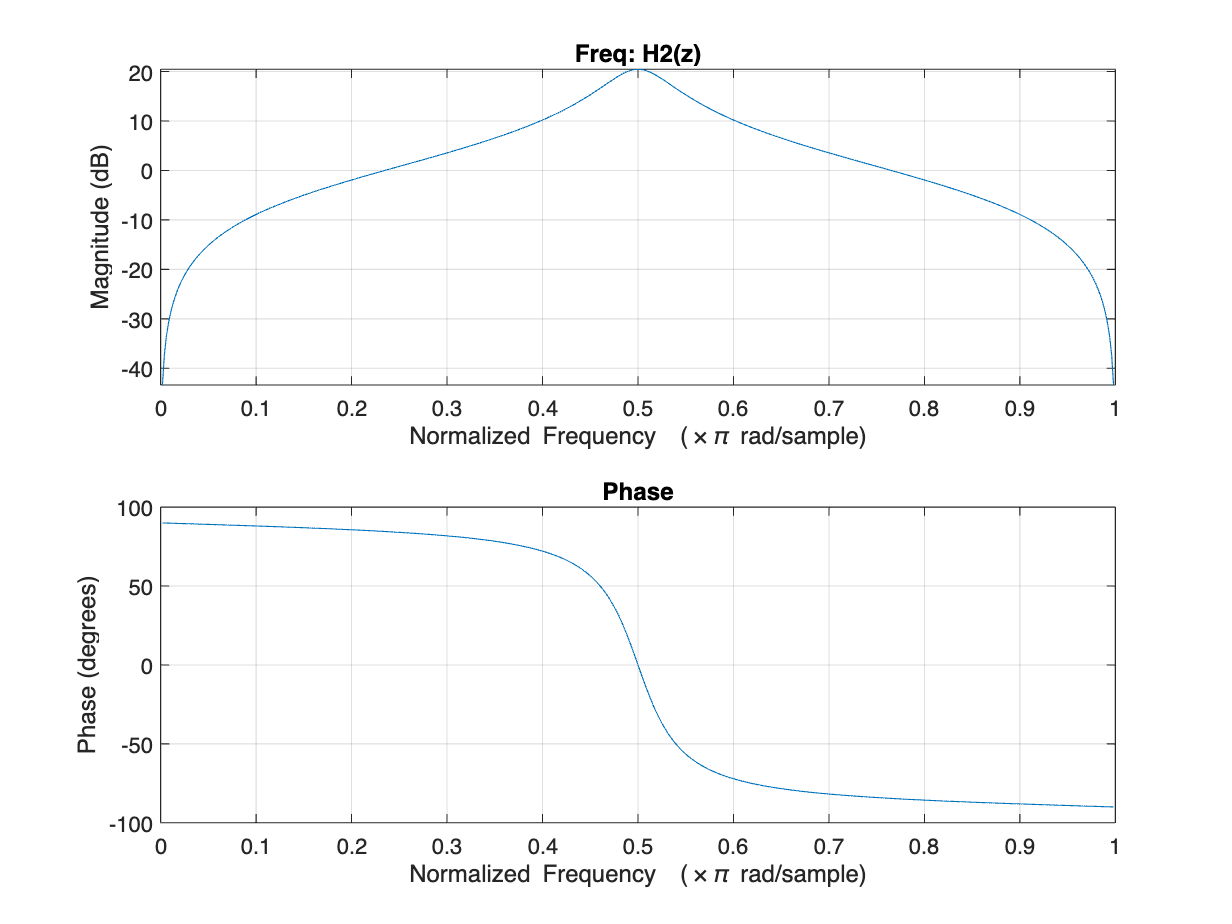

[num, den] = numden(H2);
b = sym2poly(num);
a = sym2poly(den);

figure;
subplot(1,2,1);
freqz(b, a, 512);
title('Freq: H2(z)');

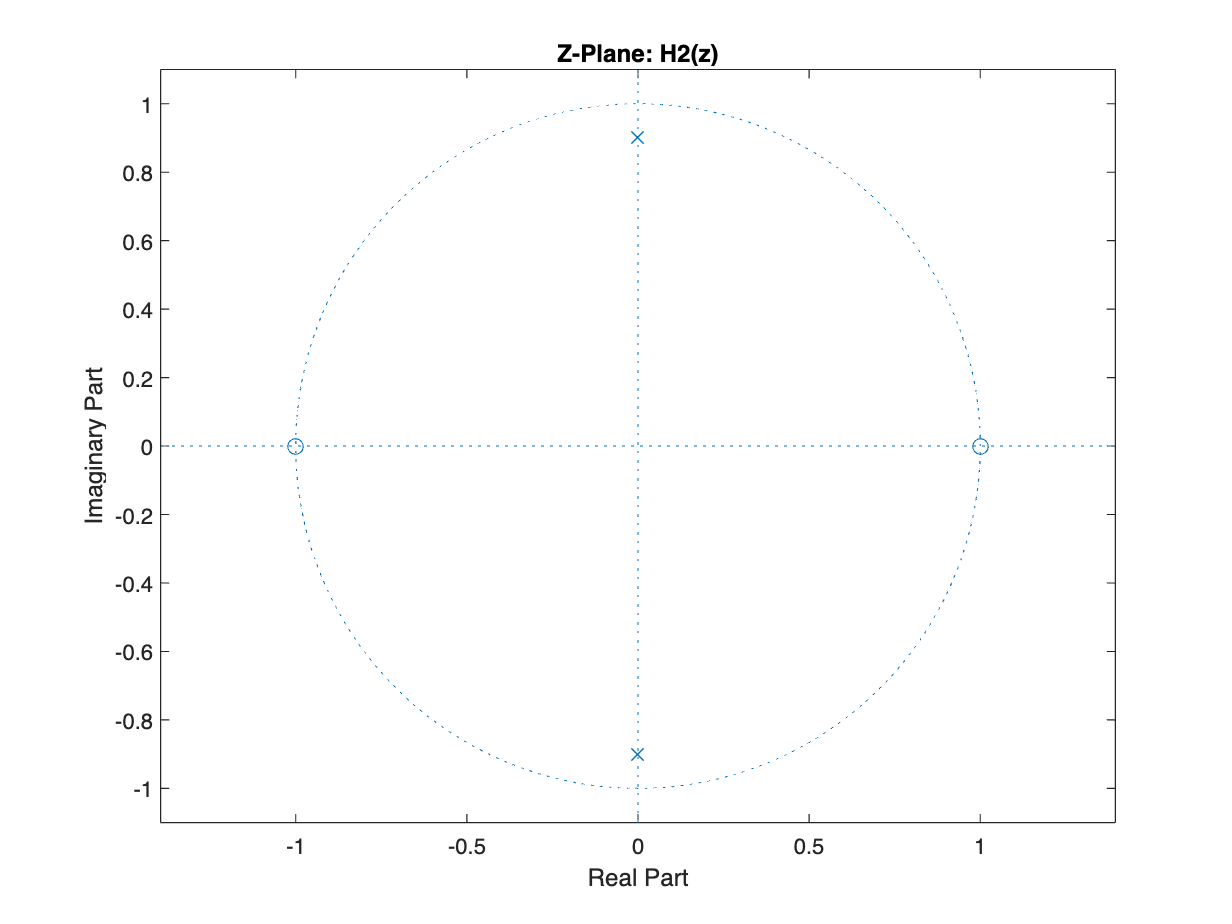

figure;
zplane(b, a);
title('Z-Plane: H2(z)');

**Find the poles and zeros of the new filters and explain how they are related to the poles and zeros of the original filters.**

    Zeros (H1): z = -j, j

    Poles (H1): z = -0.9j, 0.9j

    Zeros (H2): z = -1, 1

    Poles (H2): z = -0.9j, 0.9j

**What kind of filter is each of the new filters?**

    H1: Band-stop

    H2: Band-pass

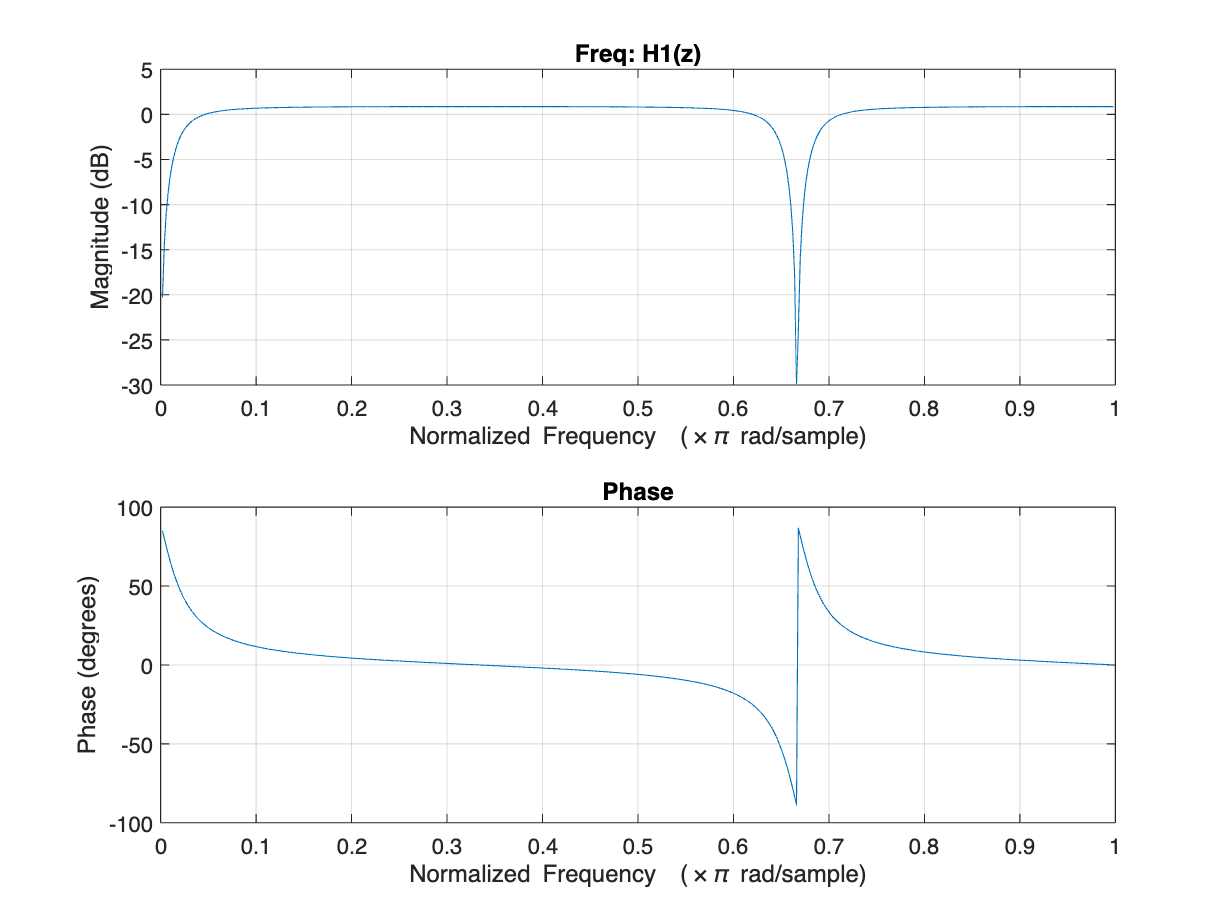

% Part c
syms z;
H1 = (z^3 - 1)/(z^3 - 0.81);
H2 = (z^3 + 1)/(z^3 - 0.81);

[num, den] = numden(H1);
b = sym2poly(num);
a = sym2poly(den);

figure;
subplot(1,2,1);
freqz(b, a, 512);
title('Freq: H1(z)');

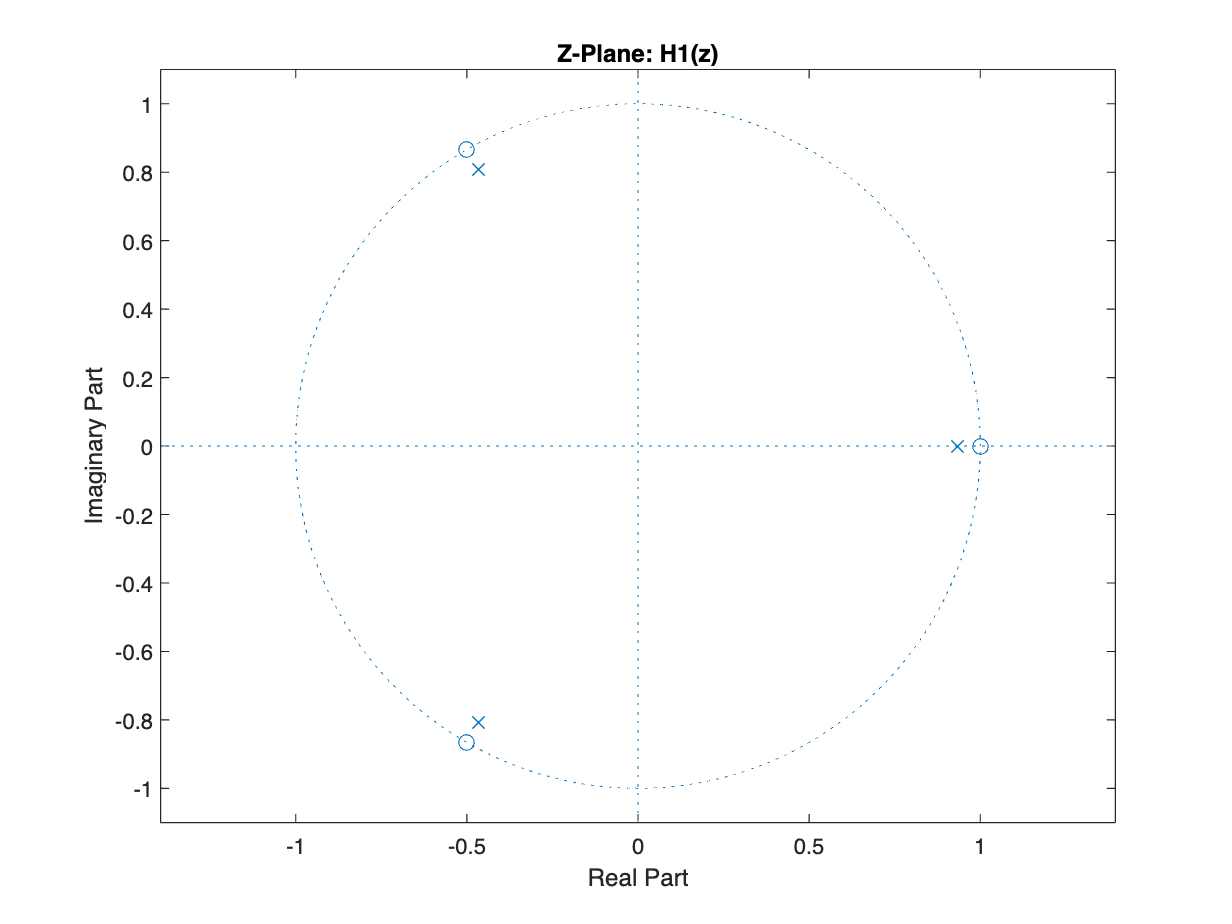

figure;
zplane(b, a);
title('Z-Plane: H1(z)');

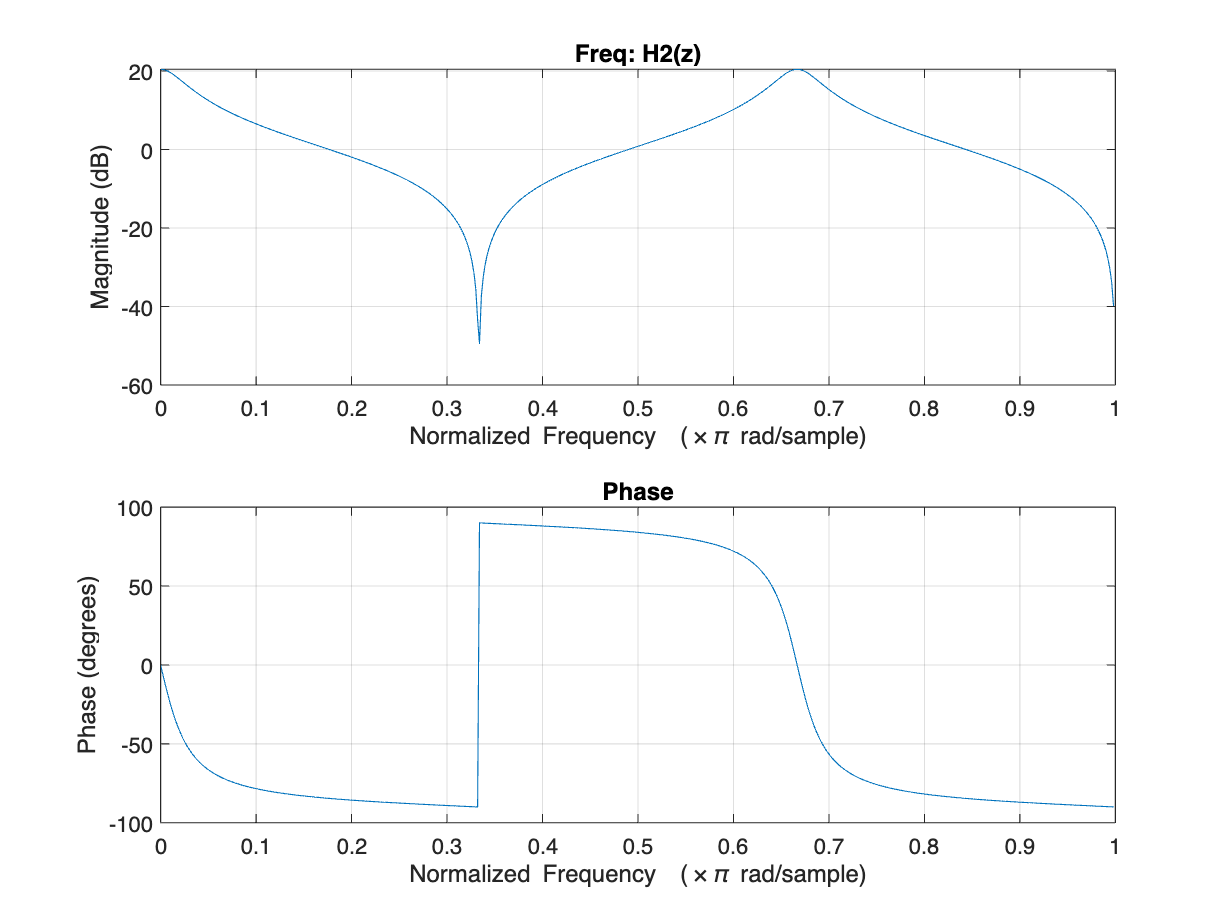

[num, den] = numden(H2);
b = sym2poly(num);
a = sym2poly(den);

figure;
subplot(1,2,1);
freqz(b, a, 512);
title('Freq: H2(z)');

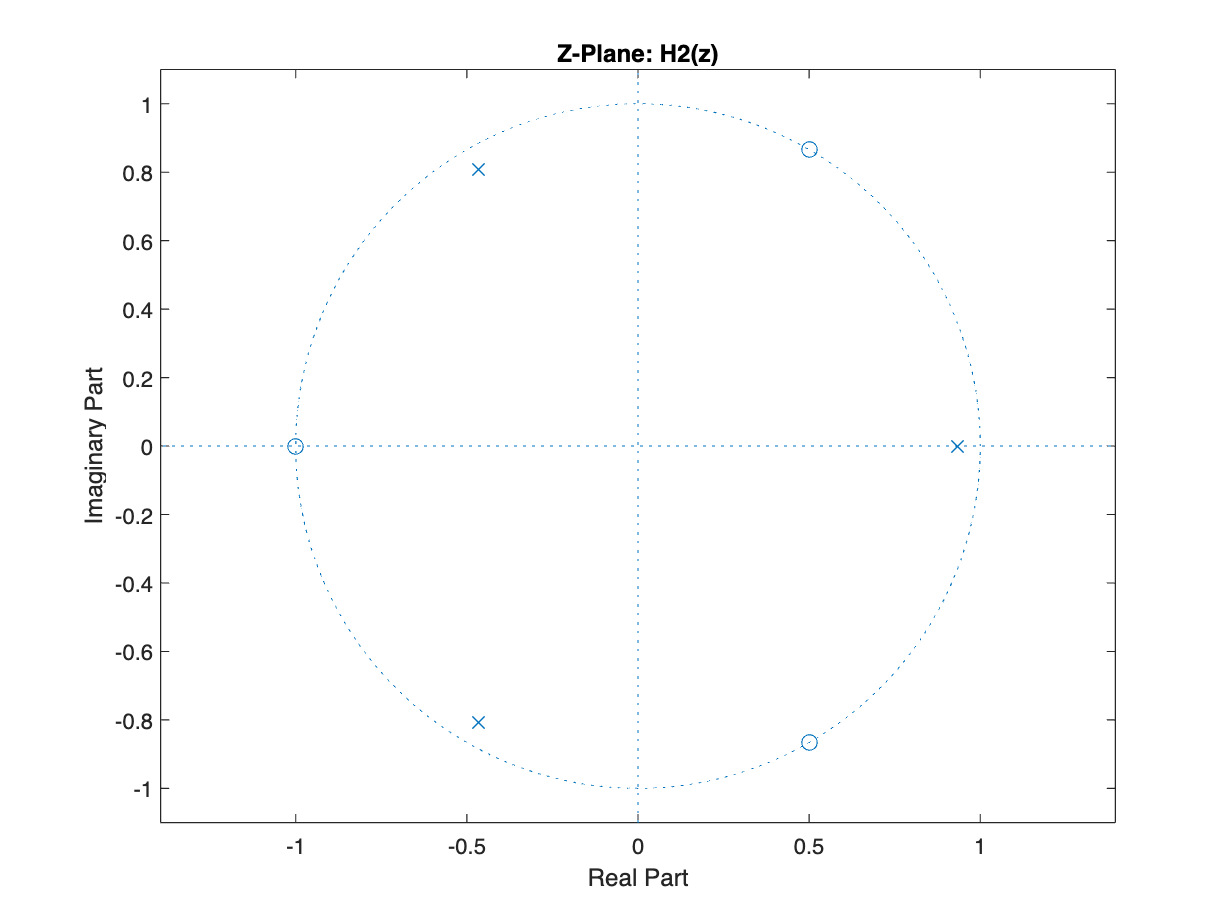

figure;
zplane(b, a);
title('Z-Plane: H2(z)');

**Find the poles and zeros of the new filters and explain how they are related to the poles and zeros of the original filters.**

    Zeros (H1): z = -1, 1

    Poles (H1): z = 3rd root of 0.81

    Zeros (H2): z = 3rd root of -1

    Poles (H2): z = 3rd root of 0.81

**What kind of filter is each of the new filters?**

    H1: Multi-band

    H2: Multi-band

## Question 7

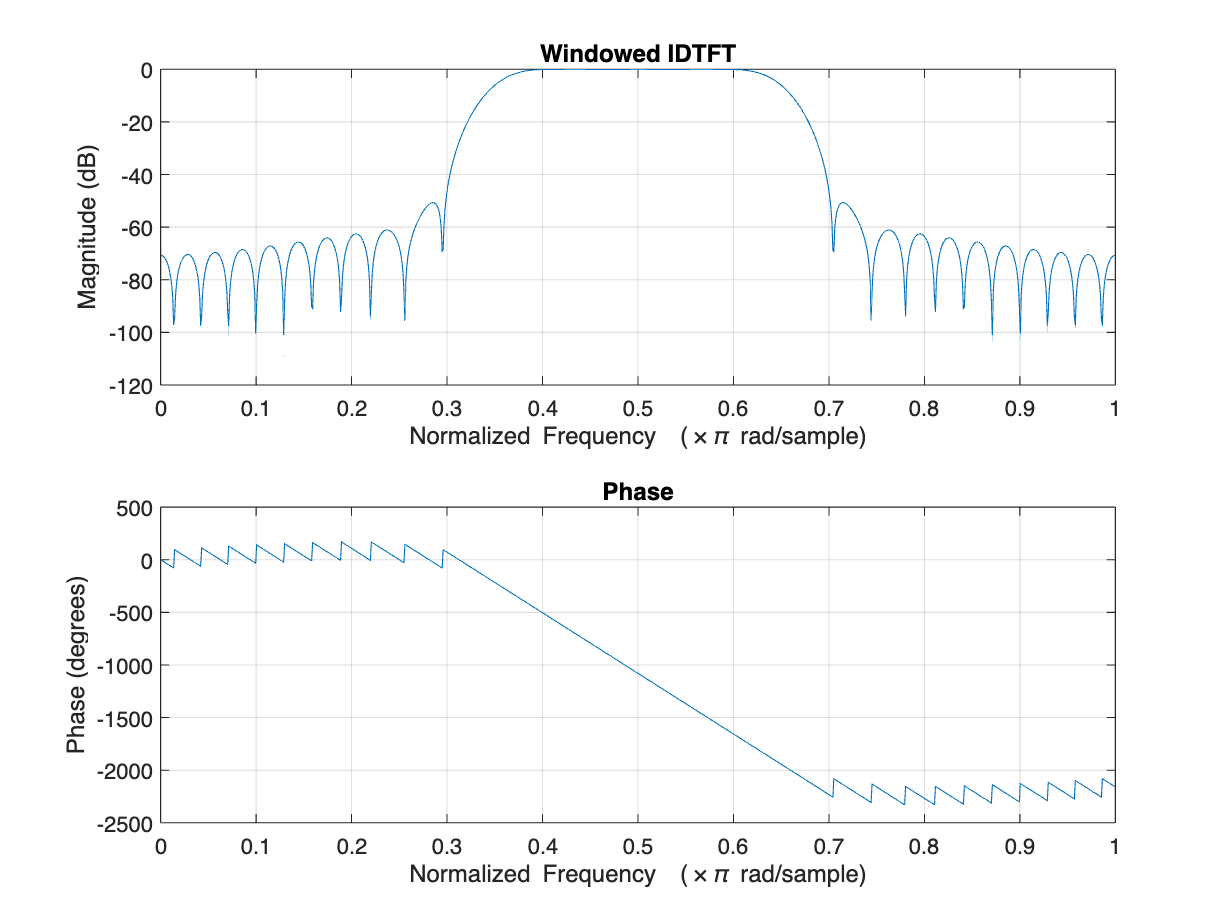

% Part a
n = 64;
fv = [1400 2600]/4000;
b = fir1(n, fv, 'DC-0');
figure; freqz(b, 1, 1024);
title('Windowed IDTFT');

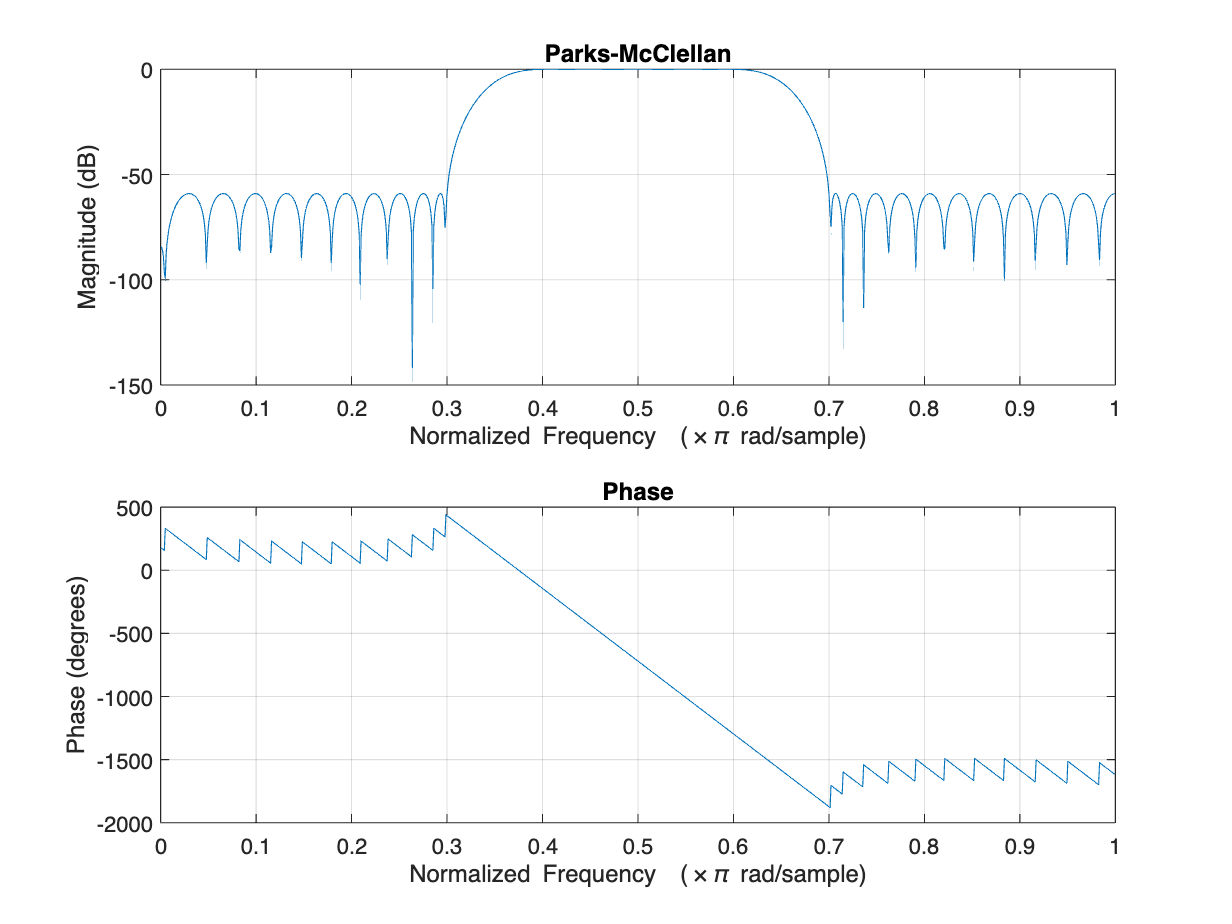

% Part b
f_pm = [0,1200,1600,2400,2800,4000]/4000;
a_pm = [0,0,1,1,0,0];
b_pm = firpm(n,f_pm,a_pm);
figure;
freqz(b_pm, 1, 1024);
title('Parks-McClellan');

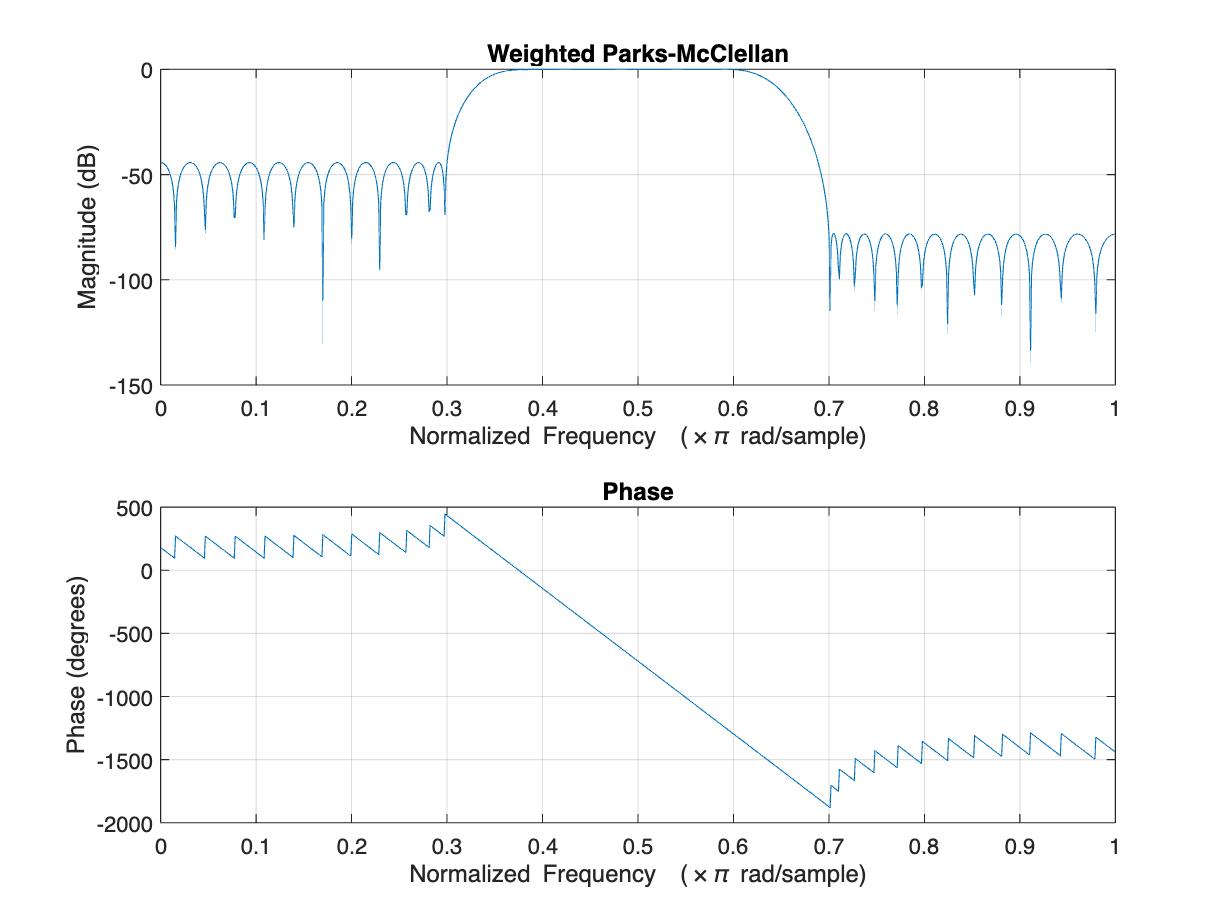

% Part c
w_pm = [1,1,50];
b_pm = firpm(n,f_pm,a_pm,w_pm);
figure;
freqz(b_pm, 1, 1024);
title('Weighted Parks-McClellan');